% Path 2 Data
% Path2AllData = '/Volumes/Julie4T/Results';
Path2AllData = '/Users/elie/Documents/LMCResults';
addpath(genpath('/Users/elie/Documents/CODE/GeneralCode'))
ADBitVolts_sorting=500/32767; %Conversion value used in mat2ntt for proper ploting under spikesort3D in AD count
% Let's find the date of interest in the Google sheet
% Path2RecordingTable = '/Users/elie/Google Drive/BatmanData/RecordingLogs/recording_logs.xlsx';
% [~,~,RecTableData]=xlsread(Path2RecordingTable,1,'A1:AF200','basic');
% Header = RecTableData(1,:);
% ND_IDCol = find(contains(Header, 'Neural data voc in operant + PSTH'));
% BatIDCol = find(contains(Header, 'Bat'));
% NLCol = find(contains(Header, 'NL'));
% Dates_Ind = find(cell2mat(RecTableData(2:end,ND_IDCol))==1)+1;
% Dates = cell2mat(RecTableData(Dates_Ind,1));
ThreshSig=50;

## Loop through spike sorting units and evaluate quality

SubjectID = '59834';
ListSSU = dir(fullfile(Path2AllData, sprintf('%s*.mat',SubjectID)));
NU = length(ListSSU);
% get rid of files that corresponds to individual experiments
Data2Keep = nan(1,NU);
for ss=1:NU
    Data2Keep(ss) = length(strfind(ListSSU(ss).name, '_'))==3;
end
ListSSU = ListSSU(find(Data2Keep));
NU = length(ListSSU);

SSQ = cell(NU,1);
SNR = nan(NU,1);
ContamInd = nan(NU,1);
ISIViolation = nan(NU,1);
for ss=1:NU
    fprintf(1,'File %d/%d\n',ss,NU)
    [~,FileName] = fileparts(ListSSU(ss).name);
%     Ind_ = strfind(FileName,'_');
%     SubjectID = FileName(1:5);
%     Date = FileName(7:14);
%     TetrodeID = FileName(Ind_(3)+1);
%     SSQ = FileName(Ind_(3)-1);
%     Ind__ = strfind(FileName,'-');
%     SSID = FileName(Ind__:end);
    Data=load(fullfile(ListSSU(ss).folder,ListSSU(ss).name));
    SNR(ss) = max(Data.QualitySSU.SNR);
    ContamInd(ss) = Data.QualitySSU.ContamInd;
    ISIViolation(ss) = Data.QualitySSU.ISIViolation;
    if (SNR(ss)>=5) && (ISIViolation(ss)<=1) && (ContamInd(ss)<=0.2)
        SSQ{ss} = 'SSSU';
    elseif (SNR(ss)>=2)
        SSQ{ss} = 'SSMU';
    else
        SSQ{ss} = 'NOISE';
    end
end

File 1/488
File 2/488
File 3/488
File 4/488
File 5/488
File 6/488
File 7/488
File 8/488
File 9/488
File 10/488
File 11/488
File 12/488
File 13/488
File 14/488
File 15/488
File 16/488
File 17/488
File 18/488
File 19/488
File 20/488
File 21/488
File 22/488
File 23/488
File 24/488
File 25/488
File 26/488
File 27/488
File 28/488
File 29/488
File 30/488
File 31/488
File 32/488
File 33/488
File 34/488
File 35/488
File 36/488
File 37/488
File 38/488
File 39/488
File 40/488
File 41/488
File 42/488
File 43/488
File 44/488
File 45/488
File 46/488
File 47/488
File 48/488
File 49/488
File 50/488
File 51/488
File 52/488
File 53/488
File 54/488
File 55/488
File 56/488
File 57/488
File 58/488
File 59/488
File 60/488
File 61/488
File 62/488
File 63/488
File 64/488
File 65/488
File 66/488
File 67/488
File 68/488
File 69/488
File 70/488
File 71/488
File 72/488
File 73/488
File 74/488
File 75/488
File 76/488
File 77/488
File 78/488
File 79/488
File 80/488
File 81/488
File 82/488
File 83/488
File 84/488
F

SSSU = (SNR>=5) .* (ISIViolation<=1) .* (ContamInd<=0.2);
SSMU = ~SSSU .* (SNR>=2);
NOISE = SNR<2;
C = [NOISE SSSU SSMU];
fprintf('Number of single units: %d/%d, %.2f%%\n',sum(SSSU), NU,sum(SSSU)/NU*100)

Number of single units: 139/488, 28.48%


fprintf('Number of multi-units: %d/%d, %.2f%%\n',sum(SSMU), NU,sum(SSMU)/NU*100)

Number of multi-units: 347/488, 71.11%


fprintf('Number of Noise units: %d/%d, %.2f%%\n',sum(NOISE), NU,sum(NOISE)/NU*100)

Number of Noise units: 2/488, 0.41%


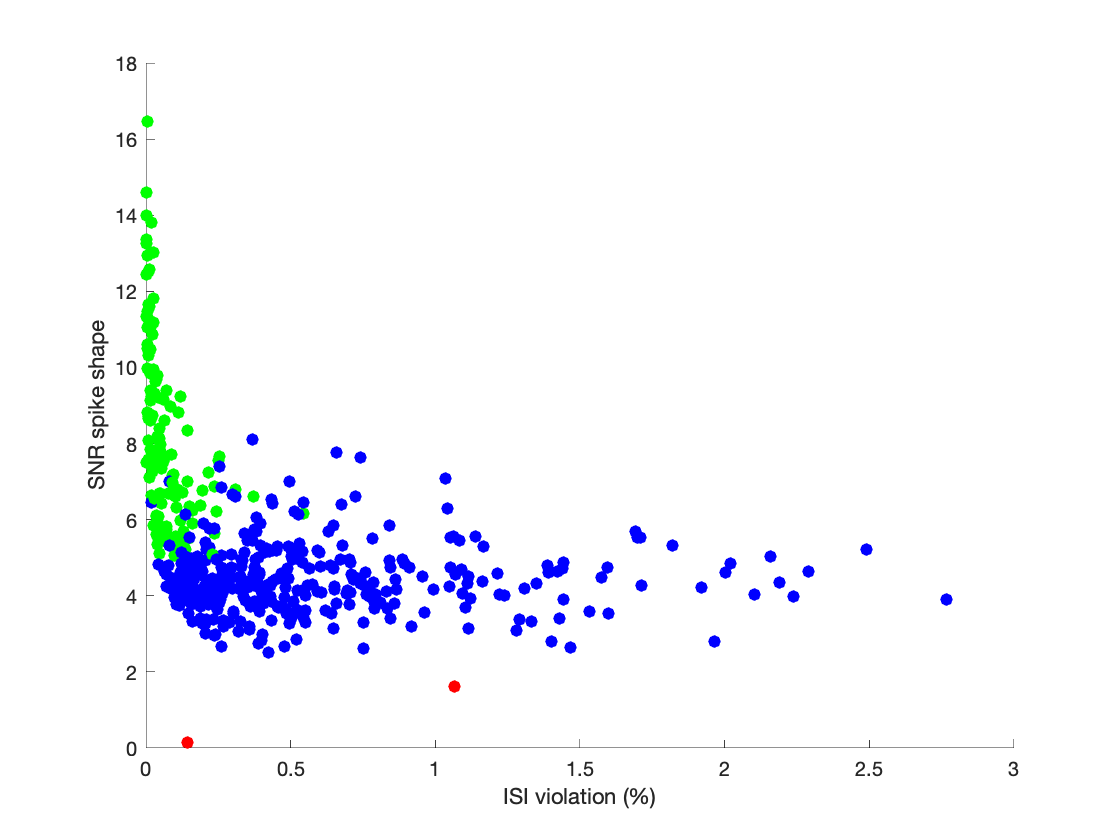


% GoodCellIndices = find(contains(SSQ, 'SS'));

% C = [contains(SSQ, 'NOISE') contains(SSQ, 'SSSU') contains(SSQ, 'SSMU')];
scatter(ISIViolation, SNR,40,C,'filled')
xlabel('ISI violation (%)')
ylabel('SNR spike shape')

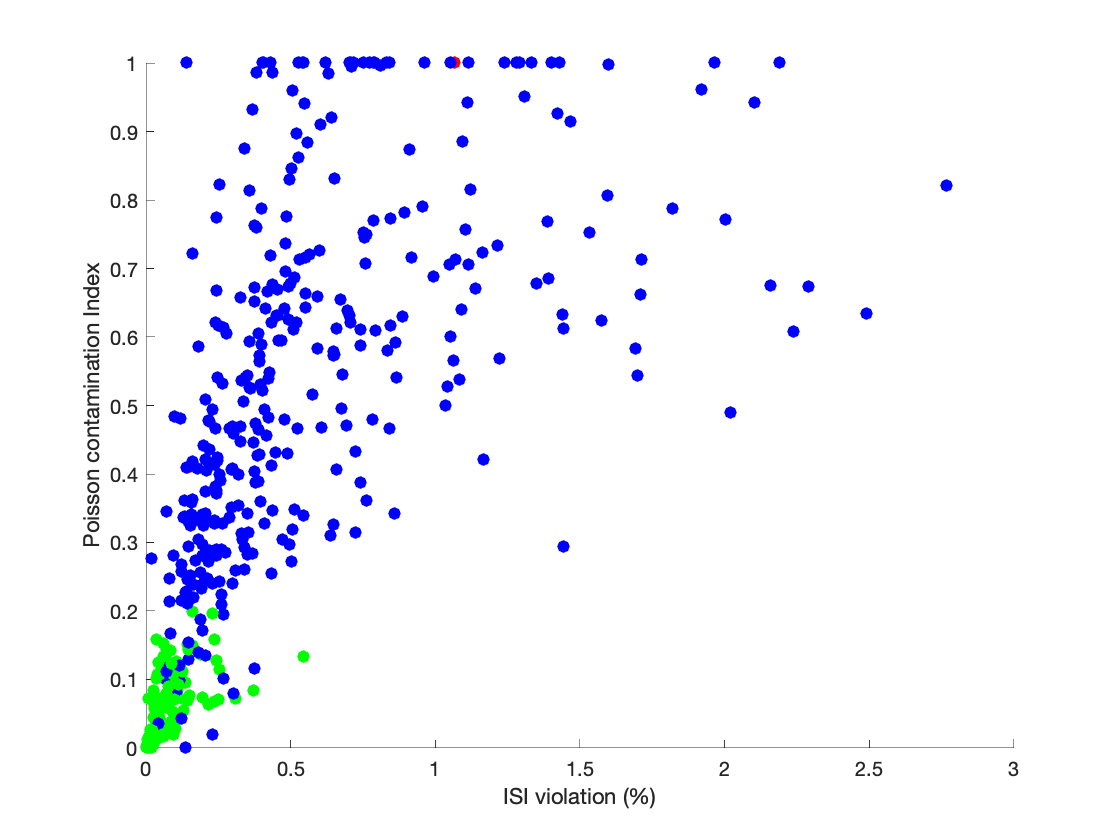

ContamInd(ContamInd>1)=1; %saturate the ContamInd, everything above 1 is just highly contaminated
scatter(ISIViolation,ContamInd, 40, C,'filled')
xlabel('ISI violation (%)')
ylabel('Poisson contamination Index')

## Hierarchical clustering on KDE onset of all cells for Ba and Tr

% gather the data
Tstart = -5000;
GoodCellIndices = sort([find(SSSU); find(SSMU)]);
GC = length(GoodCellIndices);
KDE_onset = cell(GC,3);
T_onset = cell(GC,2);
Tmax = nan(GC,2);
MeanKDEBaTr = nan(GC,1);
StdKDEBaTr = nan(GC,1);
MeanKDEAllVoc = nan(GC,1);
StdKDEAllVoc = nan(GC,1);
for ss=1:GC
    fprintf(1,'File %d/%d\n',ss,GC)
    [~,FileName] = fileparts(ListSSU(GoodCellIndices(ss)).name);
    Data=load(fullfile(ListSSU(GoodCellIndices(ss)).folder,ListSSU(GoodCellIndices(ss)).name));
    if isfield(Data,'KDE_onset') && isfield(Data.KDE_onset, 'SelfBaOp')
        Tmax(ss,1) = max(Data.KDE_onset.SelfBaOp(2,:));
        KDE_onset{ss,1} = Data.KDE_onset.SelfBaOp(1,find(Data.KDE_onset.SelfBaOp(2,:)==Tstart):end);
    end
    if isfield(Data,'KDE_onset') && isfield(Data.KDE_onset, 'SelfTrOp')
        Tmax(ss,2) = max(Data.KDE_onset.SelfTrOp(2,:));
        KDE_onset{ss,2} = Data.KDE_onset.SelfTrOp(1,find(Data.KDE_onset.SelfTrOp(2,:)==Tstart):end);
    end
    if isfield(Data,'KDE_onset') && isfield(Data.KDE_onset, 'SelfVocOp')
        KDE_onset{ss,3} = Data.KDE_onset.SelfVocOp(1,find(Data.KDE_onset.SelfVocOp(2,:)==Tstart):end);
        MeanKDEAllVoc(ss) = nanmean(KDE_onset{ss,3}); 
        StdKDEAllVoc(ss) = nanstd(KDE_onset{ss,3}); 
    end
    MeanKDEBaTr(ss) = nanmean([KDE_onset{ss,1} KDE_onset{ss,2}]); 
    StdKDEBaTr(ss) = nanstd([KDE_onset{ss,1} KDE_onset{ss,2}]); 
end

File 1/486
File 2/486
File 3/486
File 4/486
File 5/486
File 6/486
File 7/486
File 8/486
File 9/486
File 10/486
File 11/486
File 12/486
File 13/486
File 14/486
File 15/486
File 16/486
File 17/486
File 18/486
File 19/486
File 20/486
File 21/486
File 22/486
File 23/486
File 24/486
File 25/486
File 26/486
File 27/486
File 28/486
File 29/486
File 30/486
File 31/486
File 32/486
File 33/486
File 34/486
File 35/486
File 36/486
File 37/486
File 38/486
File 39/486
File 40/486
File 41/486
File 42/486
File 43/486
File 44/486
File 45/486
File 46/486
File 47/486
File 48/486
File 49/486
File 50/486
File 51/486
File 52/486
File 53/486
File 54/486
File 55/486
File 56/486
File 57/486
File 58/486
File 59/486
File 60/486
File 61/486
File 62/486
File 63/486
File 64/486
File 65/486
File 66/486
File 67/486
File 68/486
File 69/486
File 70/486
File 71/486
File 72/486
File 73/486
File 74/486
File 75/486
File 76/486
File 77/486
File 78/486
File 79/486
File 80/486
File 81/486
File 82/486
File 83/486
File 84/486
F

save('explore_populationSU_data.mat')

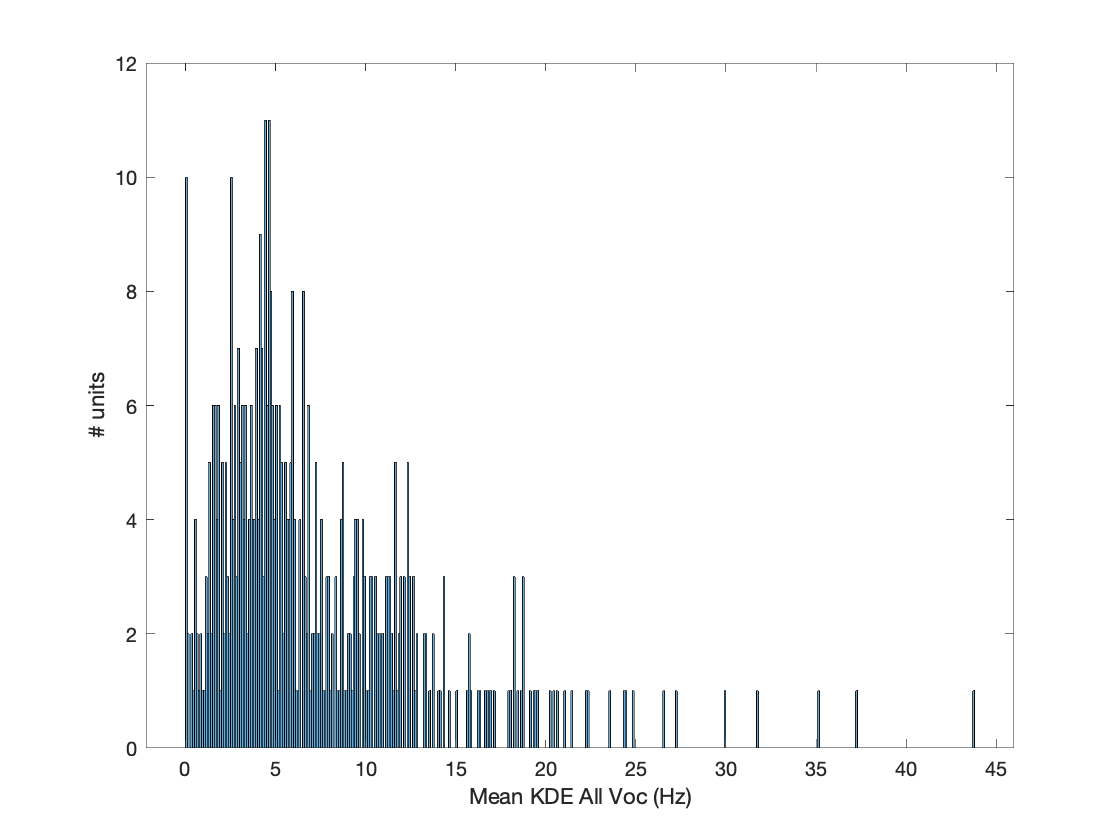

% Explore the average spike rates and get rid of non active cells?
histogram(MeanKDEAllVoc,'BinWidth',0.1)
xlabel('Mean KDE All Voc (Hz)')
ylabel('# units')

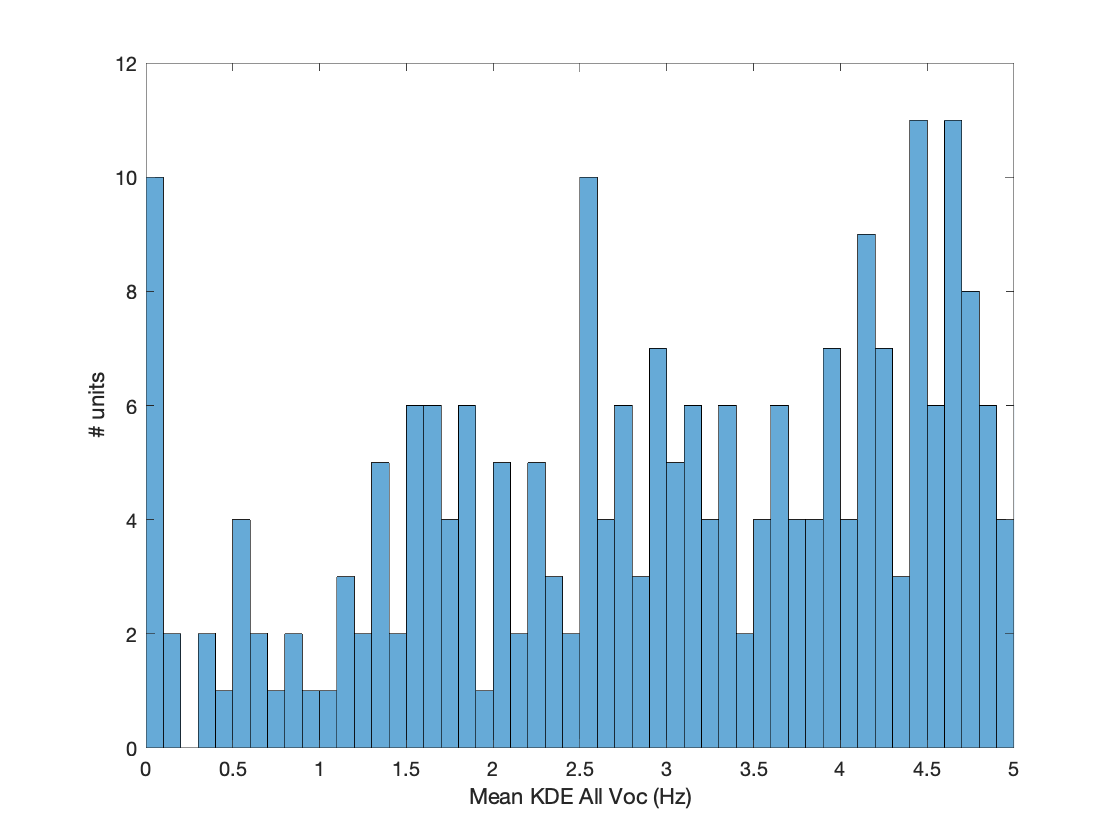

histogram(MeanKDEAllVoc,'BinWidth',0.1)
xlabel('Mean KDE All Voc (Hz)')
ylabel('# units')
xlim([0 5])

ActiveCells = find(MeanKDEAllVoc>0.1);
fprintf(1,'Number of active cells: %d',length(ActiveCells))

Number of active cells: 476

% Trim the data of active cells in time and create a matrix of all the z-scored KDE

BaTr_0ind = ~isnan(Tmax(:,1)) .* ~isnan(Tmax(:,2)).* ~isnan(MeanKDEBaTr).*MeanKDEAllVoc>0.1;
BaTr_Ind = find(BaTr_0ind);
fprintf('The clustering algorithm can be performed on the data of %d/%d\n',sum(BaTr_0ind),length(ActiveCells))

The clustering algorithm can be performed on the data of 397/476


TBa = length(Tstart:min(Tmax(:,1)));
TTr = length(Tstart:min(Tmax(:,2)));
KDE_onset_Mat_BaTr_ZS_noTrim = nan(sum(BaTr_0ind),TBa + TTr);
for ss=1:sum(BaTr_0ind)
    fprintf(1,'File %d/%d\n',ss,sum(BaTr_0ind))
    KDE_onset_Mat_BaTr_ZS_noTrim(ss,:) = ([KDE_onset{BaTr_Ind(ss),1}(1:TBa) KDE_onset{BaTr_Ind(ss),2}(1:TTr)]-MeanKDEBaTr(BaTr_Ind(ss)))/StdKDEBaTr(BaTr_Ind(ss));
end

File 1/397
File 2/397
File 3/397
File 4/397
File 5/397
File 6/397
File 7/397
File 8/397
File 9/397
File 10/397
File 11/397
File 12/397
File 13/397
File 14/397
File 15/397
File 16/397
File 17/397
File 18/397
File 19/397
File 20/397
File 21/397
File 22/397
File 23/397
File 24/397
File 25/397
File 26/397
File 27/397
File 28/397
File 29/397
File 30/397
File 31/397
File 32/397
File 33/397
File 34/397
File 35/397
File 36/397
File 37/397
File 38/397
File 39/397
File 40/397
File 41/397
File 42/397
File 43/397
File 44/397
File 45/397
File 46/397
File 47/397
File 48/397
File 49/397
File 50/397
File 51/397
File 52/397
File 53/397
File 54/397
File 55/397
File 56/397
File 57/397
File 58/397
File 59/397
File 60/397
File 61/397
File 62/397
File 63/397
File 64/397
File 65/397
File 66/397
File 67/397
File 68/397
File 69/397
File 70/397
File 71/397
File 72/397
File 73/397
File 74/397
File 75/397
File 76/397
File 77/397
File 78/397
File 79/397
File 80/397
File 81/397
File 82/397
File 83/397
File 84/397
F

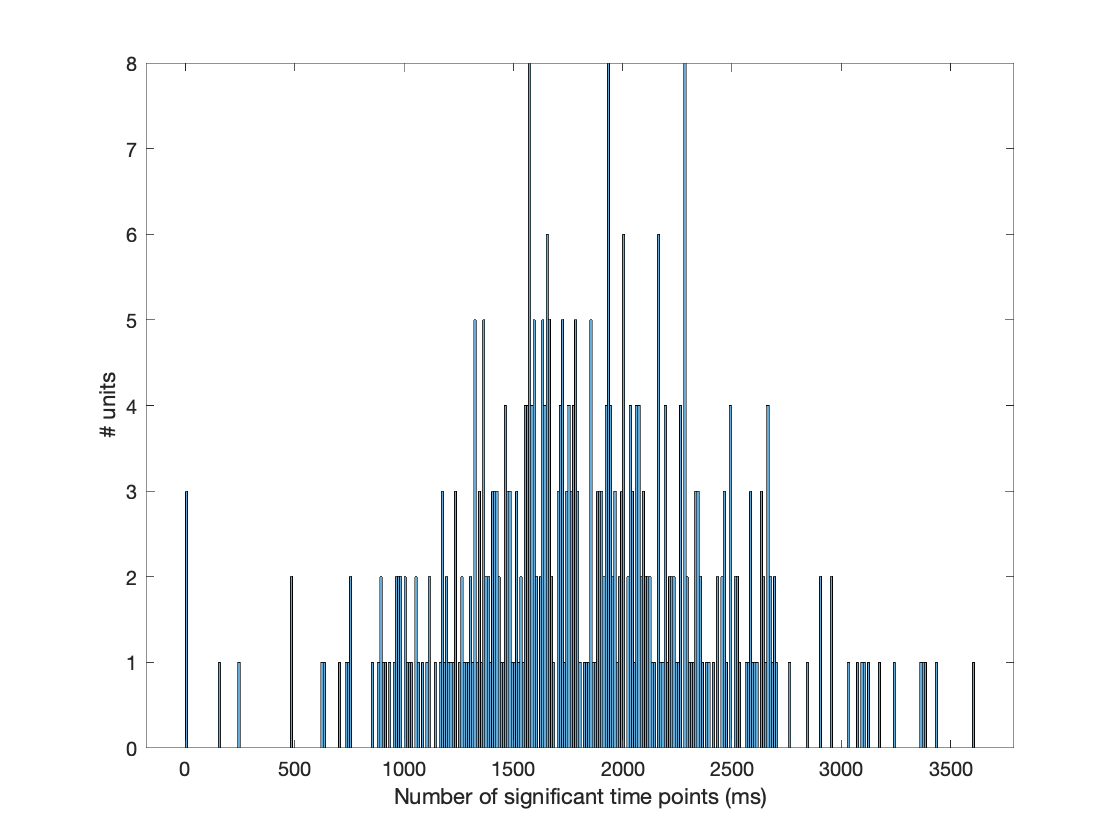

% Explore the number of time points with signficant (zscore>2) difference
% in spike rate
SignifTP = sum(abs(KDE_onset_Mat_BaTr_ZS_noTrim)>1.6,2);
histogram(SignifTP, 'BinWidth',10)
xlabel('Number of significant time points (ms)')
ylabel('# units')

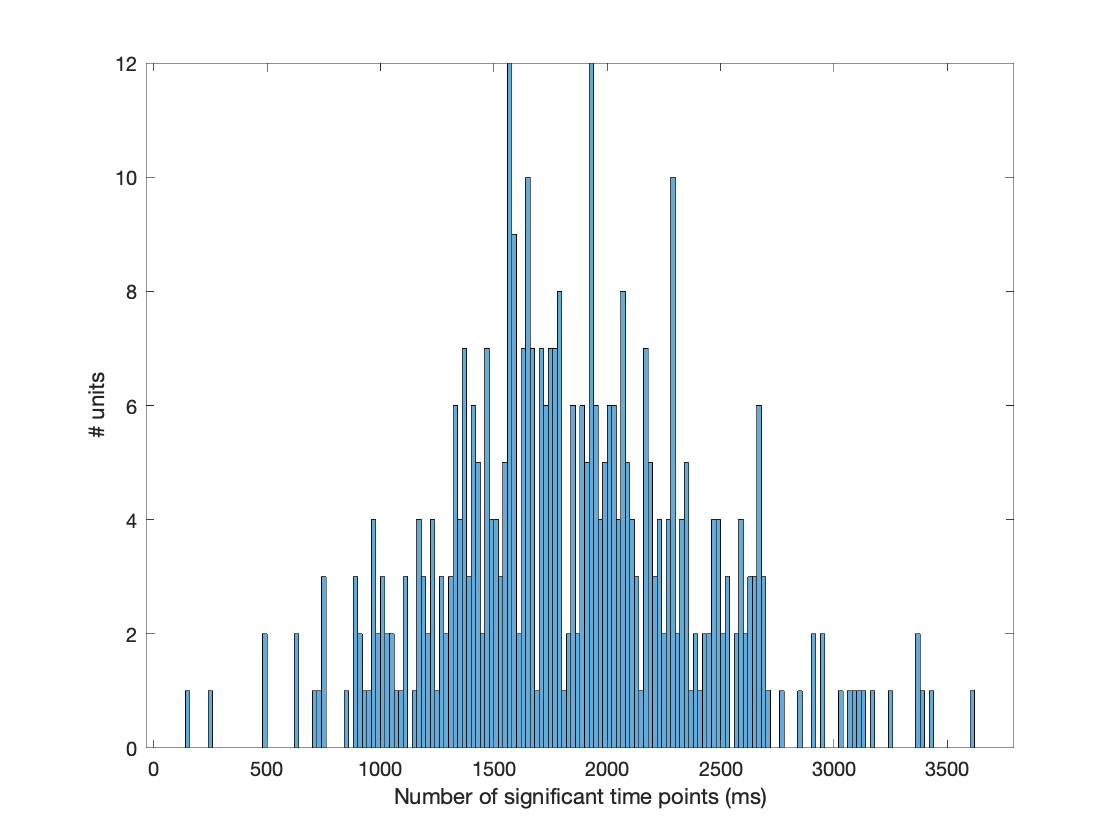

histogram(SignifTP(logical(SignifTP)), 'BinWidth',20)
xlabel('Number of significant time points (ms)')
ylabel('# units')

fprintf(1,'%d/%d (%.2f %%) units are significant\n',sum(logical(SignifTP)),length(SignifTP),100*sum(logical(SignifTP))/length(SignifTP))

394/397 (99.24 %) units are significant


fprintf(1, 'Duration of significance: %.1f +/- %.1f ms\n',mean(SignifTP(logical(SignifTP))), std(SignifTP(logical(SignifTP)))/(sum(logical(SignifTP)))^0.5)

Duration of significance: 1840.4 +/- 28.2 ms


fprintf(1,'Minimum value %.1f ms\n',min(SignifTP(logical(SignifTP))))

Minimum value 155.0 ms


fprintf(1, 'Maximum value %.1f ms\n',max(SignifTP(logical(SignifTP))))

Maximum value 3609.0 ms


ListSSUGC = ListSSU(GoodCellIndices);
ListSSUGCBaTr = ListSSUGC(BaTr_Ind);
NonSignif=find(~logical(SignifTP));
fprintf(1,'***** Checking non-significant cells ******')

***** Checking non-significant cells ******

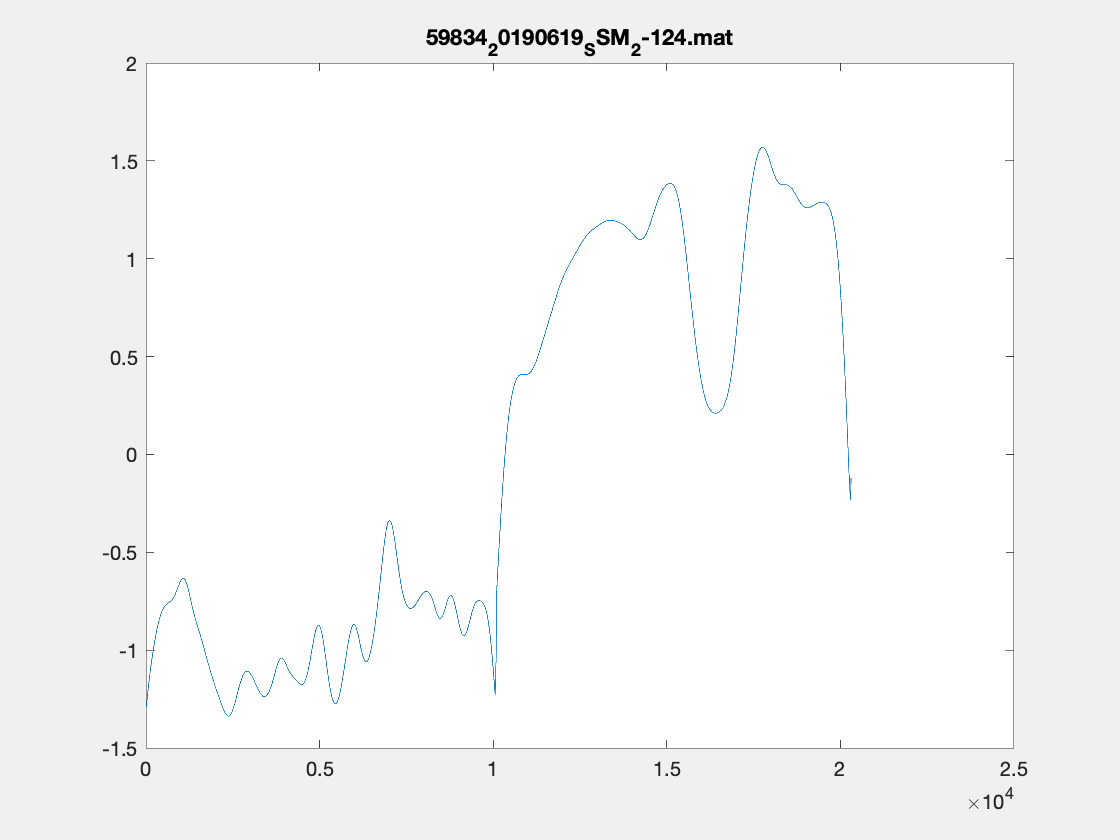

59834_20190614_SSM_1-203.mat

59834_20190614_SSS_1-193.mat

59834_20190619_SSM_2-124.mat

figure;
for ii=1:length(NonSignif)
    clc
    set(gcf, 'Visible','on')
    fprintf(1,ListSSUGCBaTr(NonSignif(ii)).name)
    plot(KDE_onset_Mat_BaTr_ZS(NonSignif(ii),:))
    title(sprintf('%s',ListSSUGCBaTr(NonSignif(ii)).name))
    pause()
end

% Restrict the dataset to significant cells
KDE_onset_Mat_BaTr_ZS = KDE_onset_Mat_BaTr_ZS_noTrim(logical(SignifTP),:);
BaTr_ind = BaTr_Ind(logical(SignifTP));

% Clustering based on zscored KDE
Z = linkage(KDE_onset_Mat_BaTr_ZS,'ward','euclidean')

Z = 	1.0e+03 *

    0.2500    0.3020    0.0256
    0.2150    0.2870    0.0268
    0.3350    0.3560    0.0292
    0.1140    0.1350    0.0295
    0.0590    0.1220    0.0303
    0.3170    0.3950    0.0320
    0.3120    0.3310    0.0354
    0.0450    0.3960    0.0355
    0.2040    0.3250    0.0370
    0.0780    0.1120    0.0371


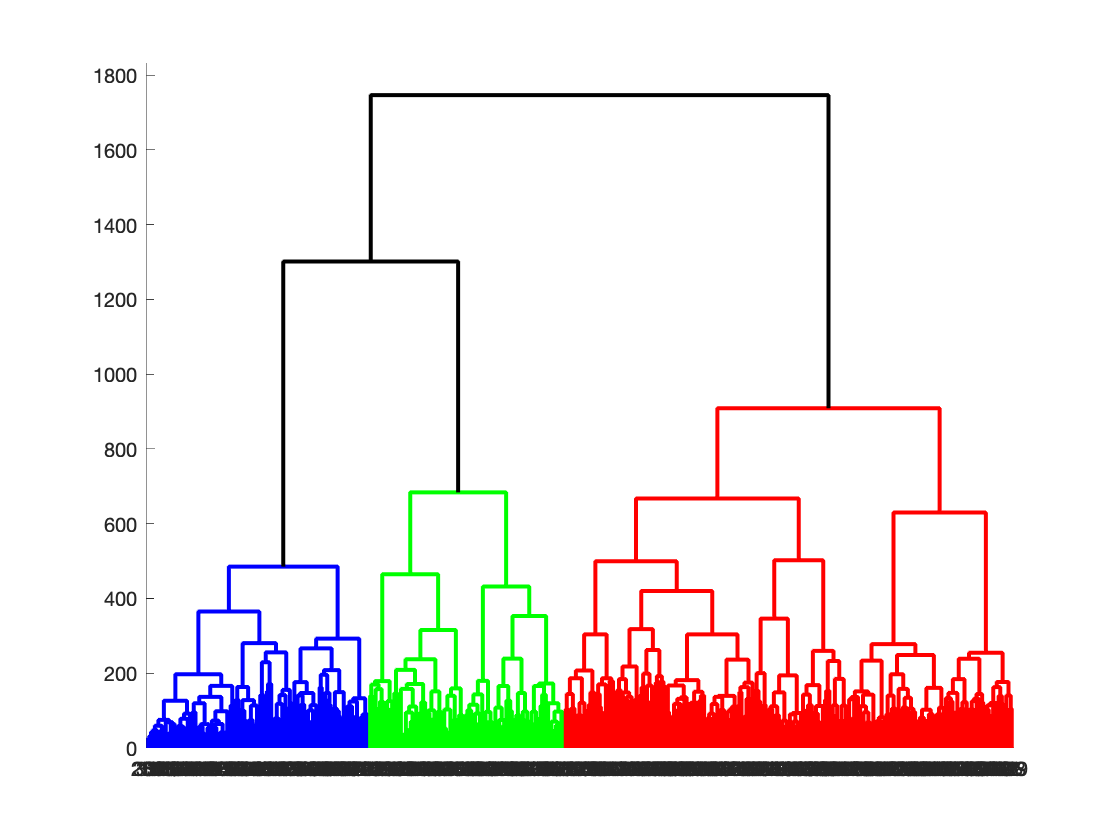

D1 = dendrogram(Z,0, 'ColorThreshold','Default');
set(D1,'LineWidth',2)

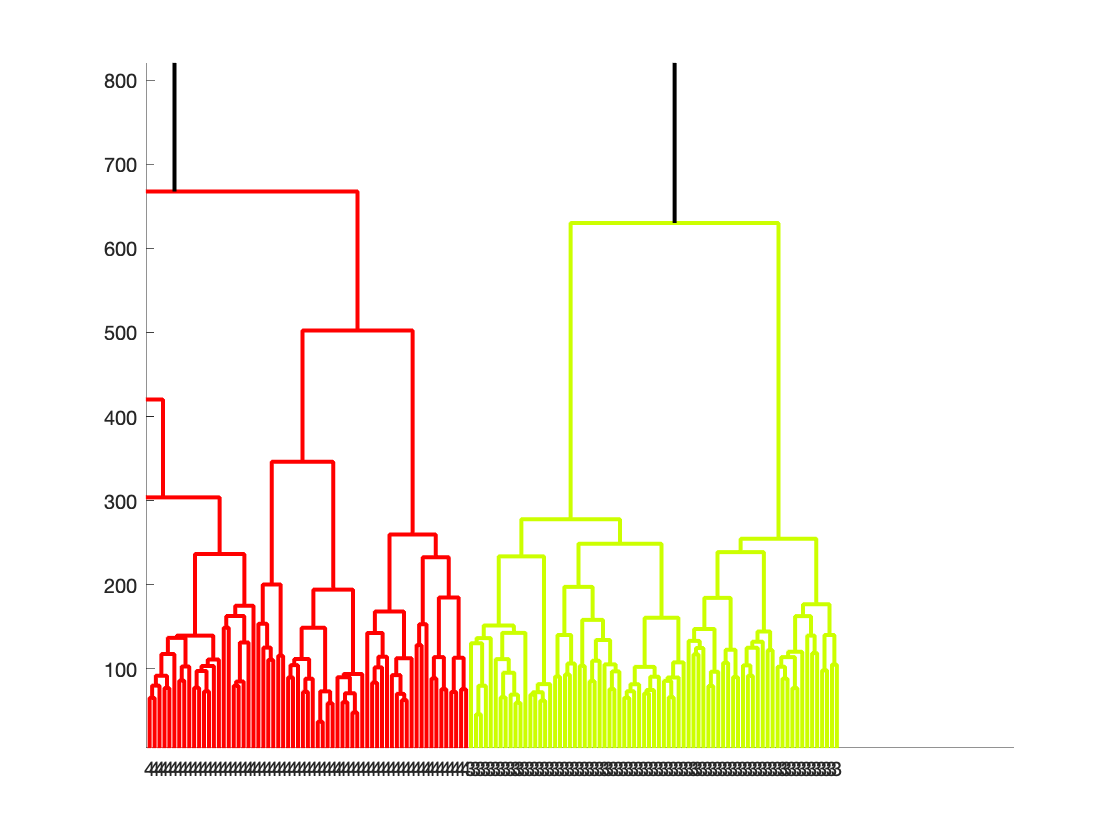

T = cluster(Z,'maxclust',5);
cutoff = median([Z(end-4,3) Z(end-3,3)]);
D2=dendrogram(Z,0,'ColorThreshold',cutoff,'Labels',num2str(T));
set(D2, 'LineWidth',2)

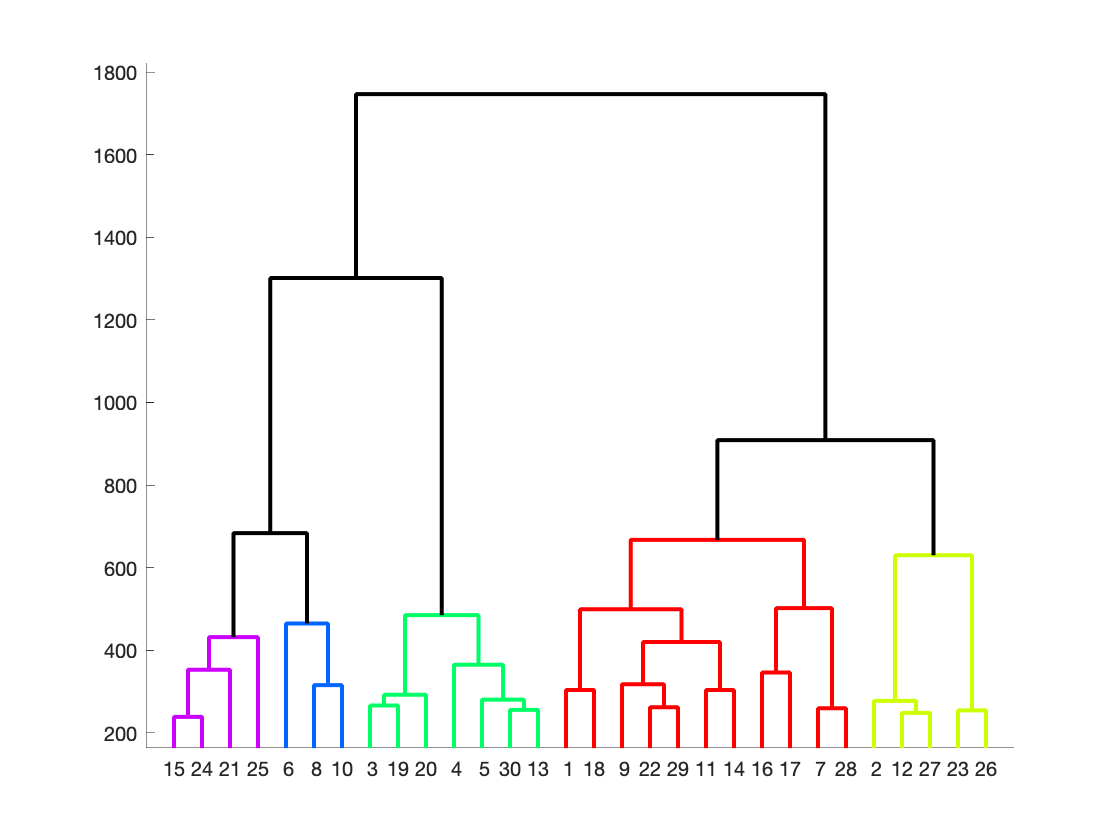

D3=dendrogram(Z,30,'ColorThreshold',cutoff,'Labels',num2str(T));
set(D3, 'LineWidth',2)

Plot the average spike rate for each cluster

CLim01 = 1;
if CLim01
    CLim = [-3 3];
end
% cluster 1
Clust=1;
IndSSU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSSU));
IndSMU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSMU));
fprintf(1,'**** Cluster %d *****\n%d units, %d single units, %d multi-units\n', Clust, sum(T==Clust),length(IndSSU),length(IndSMU))

**** Cluster 1 *****
46 units, 31 single units, 15 multi-units


for ii=1:length(IndSSU)
    fprintf('Single Unit: %s\n',ListSSU(IndSSU(ii)).name)
end

Single Unit: 59834_20190612_SSM_2-196.mat
Single Unit: 59834_20190613_SSS_2-105.mat
Single Unit: 59834_20190614_SSS_2-132.mat
Single Unit: 59834_20190616_SSS_2-83.mat
Single Unit: 59834_20190617_SSS_2-94.mat
Single Unit: 59834_20190617_SSS_3-157.mat
Single Unit: 59834_20190618_SSS_2-99.mat
Single Unit: 59834_20190618_SSS_3-176.mat
Single Unit: 59834_20190619_SSS_2-108.mat
Single Unit: 59834_20190619_SSS_3-168.mat
Single Unit: 59834_20190620_SSS_2-107.mat
Single Unit: 59834_20190621_SSM_3-167.mat
Single Unit: 59834_20190626_SSS_3-201.mat
Single Unit: 59834_20190627_SSM_3-322.mat
Single Unit: 59834_20190627_SSS_2-176.mat
Single Unit: 59834_20190628_SSS_2-118.mat
Single Unit: 59834_20190628_SSS_3-186.mat
Single Unit: 59834_20190629_SSS_2-129.mat
Single Unit: 59834_20190629_SSS_3-213.mat
Single Unit: 59834_20190630_SSS_2-128.mat
Single Unit: 59834_20190701_SSS_2-167.mat
Single Unit: 59834_20190701_SSS_3-241.mat
Single Unit: 59834_20190702_SSS_2-85.mat
Single Unit: 59834_20190702_SSS_3-187.

for ii=1:length(IndSMU)
    fprintf('Multi Unit: %s\n',ListSSU(IndSMU(ii)).name)
end

Multi Unit: 59834_20190614_SSS_3-180.mat
Multi Unit: 59834_20190618_SSM_2-119.mat
Multi Unit: 59834_20190618_SSM_2-189.mat
Multi Unit: 59834_20190619_SSM_2-134.mat
Multi Unit: 59834_20190620_SSM_2-111.mat
Multi Unit: 59834_20190620_SSM_3-145.mat
Multi Unit: 59834_20190621_SSM_2-102.mat
Multi Unit: 59834_20190622_SSM_2-128.mat
Multi Unit: 59834_20190623_SSS_2-116.mat
Multi Unit: 59834_20190627_SSM_2-182.mat
Multi Unit: 59834_20190629_SSM_2-143.mat
Multi Unit: 59834_20190629_SSM_2-161.mat
Multi Unit: 59834_20190630_SSM_2-224.mat
Multi Unit: 59834_20190701_SSM_2-211.mat
Multi Unit: 59834_20190702_SSM_2-141.mat


fprintf(1,' Plot ZS data Cluster %d \n', Clust)

 Plot ZS data Cluster 1 


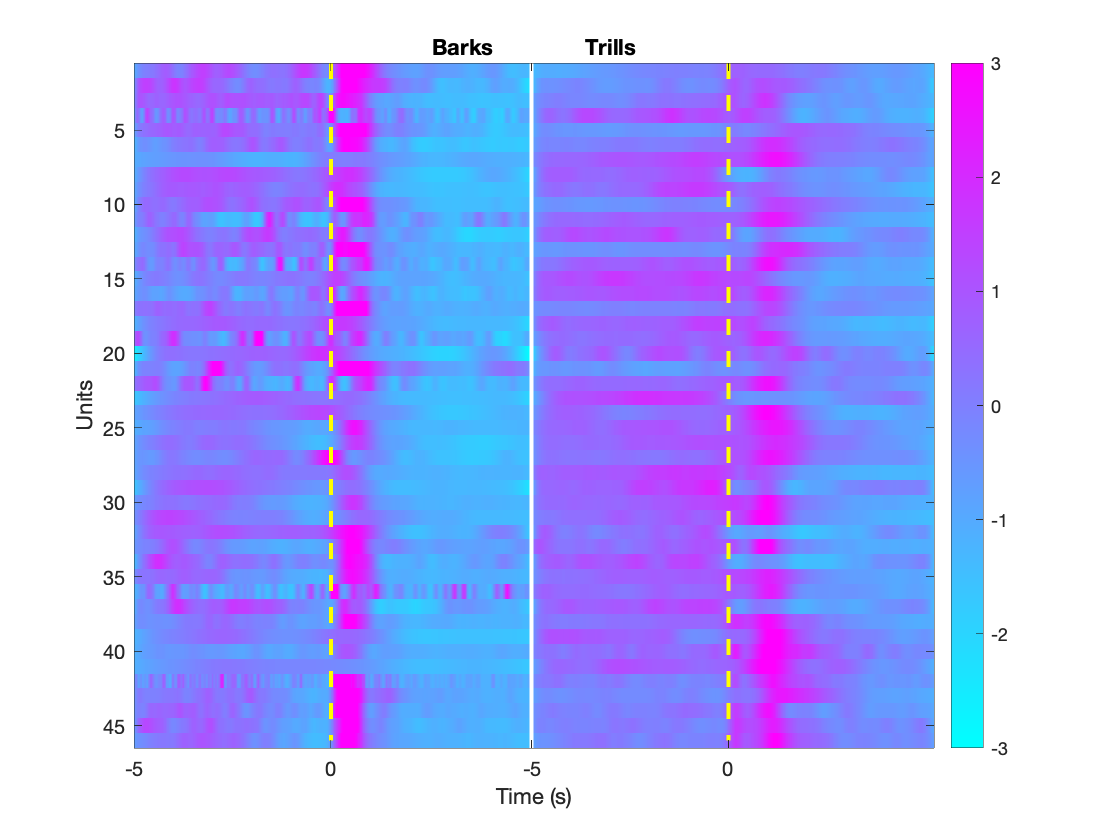

imagesc(KDE_onset_Mat_BaTr_ZS(T==Clust,:))
if CLim01
    caxis(CLim)
else
    CLim = caxis;
end
colorbar()
colormap('cool')
hold on
% delimiting Barks from Trills
line(TBa*ones(2,1), [-1 sum(T==Clust)+1],'Color', 'w', 'LineWidth',2)
hold on
% Barks onset
line([-Tstart -Tstart], [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
ylabel('Units')
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
title('Barks               Trills')
hold off

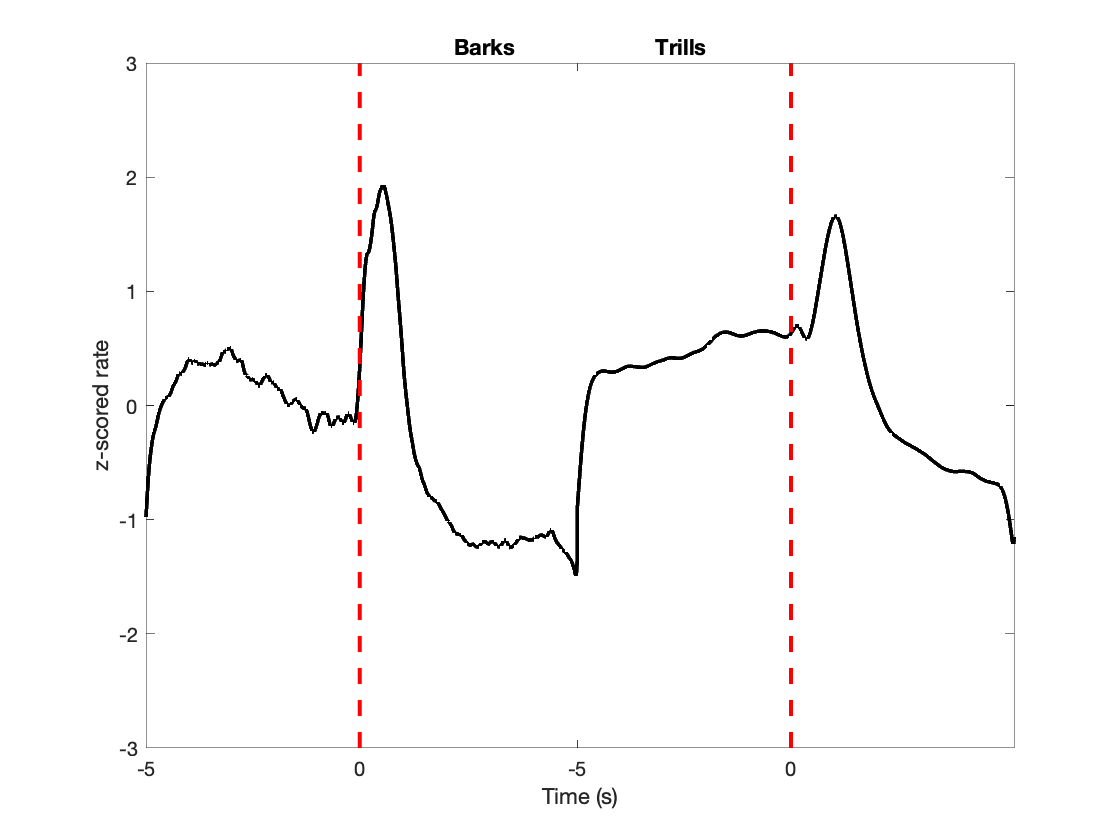


plot(mean(KDE_onset_Mat_BaTr_ZS(T==Clust,:)), 'k-', 'LineWidth',2)
xlim([0 size(KDE_onset_Mat_BaTr_ZS,2)])
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
hold on
% Barks onset
line([-Tstart -Tstart], CLim,'Color','r','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), CLim,'Color','r','LineStyle','--', 'LineWidth',2)
ylabel('z-scored rate')
title('Barks                       Trills')
hold off



% cluster 2 good example: 0612_SSS_1-81
Clust=2;
IndSSU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSSU));
IndSMU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSMU));
fprintf(1,'**** Cluster %d *****\n%d units, %d single units, %d multi-units\n', Clust, sum(T==Clust),length(IndSSU),length(IndSMU))

**** Cluster 2 *****
43 units, 12 single units, 31 multi-units


for ii=1:length(IndSSU)
    fprintf('Single Unit: %s\n',ListSSU(IndSSU(ii)).name)
end

Single Unit: 59834_20190607_SSS_1-139.mat
Single Unit: 59834_20190614_SSS_2-210.mat
Single Unit: 59834_20190616_SSS_3-202.mat
Single Unit: 59834_20190618_SSS_1-77.mat
Single Unit: 59834_20190619_SSS_1-78.mat
Single Unit: 59834_20190620_SSS_1-81.mat
Single Unit: 59834_20190621_SSS_1-76.mat
Single Unit: 59834_20190622_SSS_1-84.mat
Single Unit: 59834_20190623_SSS_1-80.mat
Single Unit: 59834_20190630_SSS_2-150.mat
Single Unit: 59834_20190704_SSS_2-134.mat
Single Unit: 59834_20190705_SSM_2-126.mat


for ii=1:length(IndSMU)
    fprintf('Multi Unit: %s\n',ListSSU(IndSMU(ii)).name)
end

Multi Unit: 59834_20190610_SSM_1-143.mat
Multi Unit: 59834_20190611_SSM_1-87.mat
Multi Unit: 59834_20190612_SSM_2-119.mat
Multi Unit: 59834_20190616_SSM_2-214.mat
Multi Unit: 59834_20190617_SSM_1-78.mat
Multi Unit: 59834_20190617_SSM_2-132.mat
Multi Unit: 59834_20190617_SSM_2-188.mat
Multi Unit: 59834_20190617_SSM_2-190.mat
Multi Unit: 59834_20190617_SSS_2-144.mat
Multi Unit: 59834_20190618_SSM_2-113.mat
Multi Unit: 59834_20190618_SSM_2-149.mat
Multi Unit: 59834_20190619_SSM_2-230.mat
Multi Unit: 59834_20190619_SSM_4-228.mat
Multi Unit: 59834_20190620_SSM_2-101.mat
Multi Unit: 59834_20190620_SSM_2-127.mat
Multi Unit: 59834_20190623_SSM_2-118.mat
Multi Unit: 59834_20190623_SSM_2-130.mat
Multi Unit: 59834_20190626_SSM_2-161.mat
Multi Unit: 59834_20190626_SSM_2-226.mat
Multi Unit: 59834_20190627_SSM_2-168.mat
Multi Unit: 59834_20190627_SSM_2-190.mat
Multi Unit: 59834_20190627_SSM_2-326.mat
Multi Unit: 59834_20190627_SSS_4-316.mat
Multi Unit: 59834_20190628_SSM_2-237.mat
Multi Unit: 59834_

fprintf(1,' Plot ZS data Cluster %d \n', Clust)

 Plot ZS data Cluster 2 


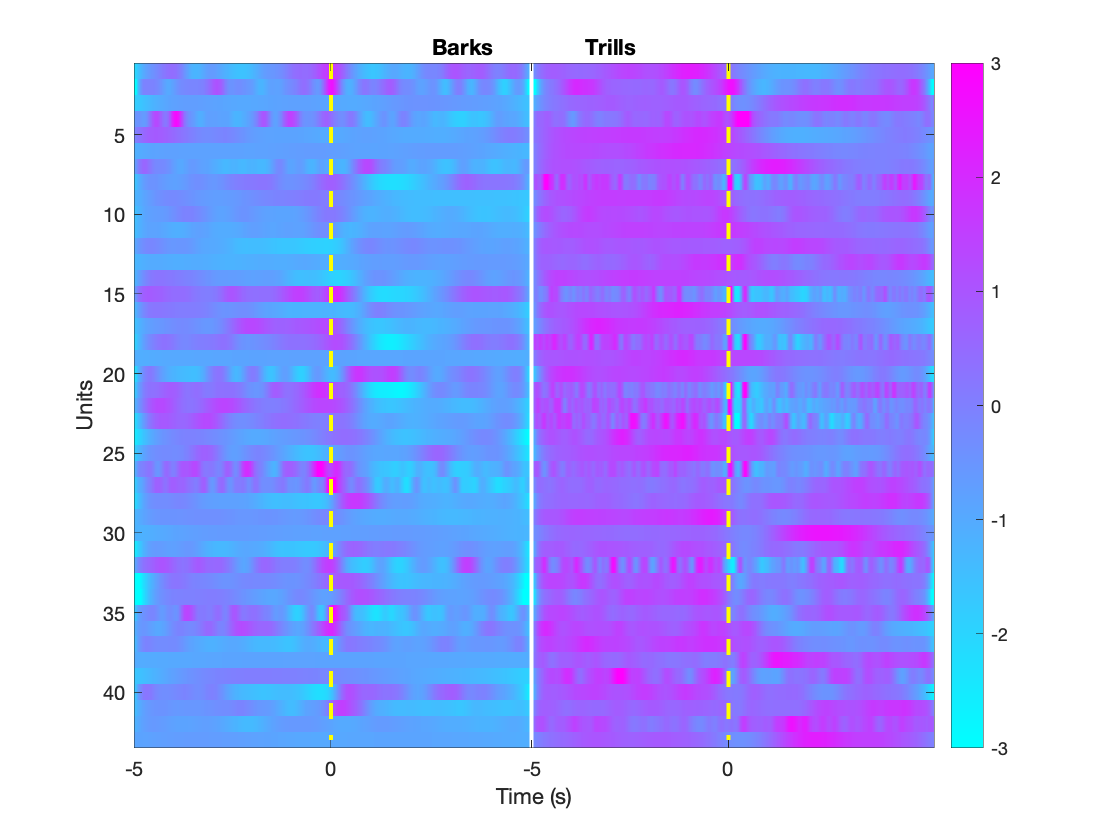

imagesc(KDE_onset_Mat_BaTr_ZS(T==Clust,:))
if CLim01
    caxis(CLim)
else
    CLim = caxis;
end
colorbar()
colormap('cool')
hold on
% delimiting Barks from Trills
line(TBa*ones(2,1), [-1 sum(T==Clust)+1],'Color', 'w', 'LineWidth',2)
hold on
% Barks onset
line([-Tstart -Tstart], [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
ylabel('Units')
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
title('Barks               Trills')
hold off

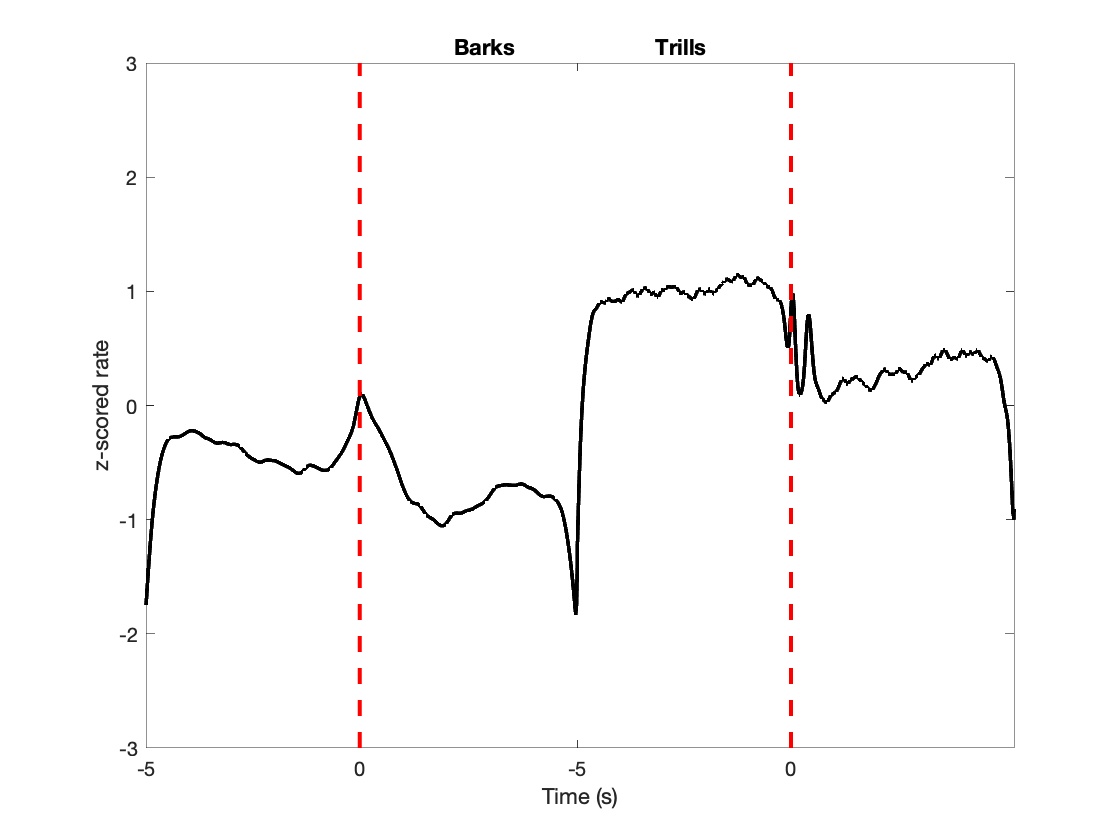


plot(mean(KDE_onset_Mat_BaTr_ZS(T==Clust,:)), 'k-', 'LineWidth',2)
xlim([0 size(KDE_onset_Mat_BaTr_ZS,2)])
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
hold on
% Barks onset
line([-Tstart -Tstart], CLim,'Color','r','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), CLim,'Color','r','LineStyle','--', 'LineWidth',2)
ylabel('z-scored rate')
title('Barks                       Trills')
hold off


% cluster 3 good example 0620_SSS_3_131
Clust=3;
IndSSU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSSU));
IndSMU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSMU));
fprintf(1,'**** Cluster %d *****\n%d units, %d single units, %d multi-units\n', Clust, sum(T==Clust),length(IndSSU),length(IndSMU))

**** Cluster 3 *****
75 units, 6 single units, 69 multi-units


for ii=1:length(IndSSU)
    fprintf('Single Unit: %s\n',ListSSU(IndSSU(ii)).name)
end

Single Unit: 59834_20190607_SSS_2-189.mat
Single Unit: 59834_20190616_SSS_3-203.mat
Single Unit: 59834_20190629_SSS_2-175.mat
Single Unit: 59834_20190705_SSS_2-261.mat
Single Unit: 59834_20190706_SSS_2-188.mat
Single Unit: 59834_20190707_SSS_2-195.mat


for ii=1:length(IndSMU)
    fprintf('Multi Unit: %s\n',ListSSU(IndSMU(ii)).name)
end

Multi Unit: 59834_20190607_SSM_1-203.mat
Multi Unit: 59834_20190611_SSM_2-220.mat
Multi Unit: 59834_20190611_SSM_3-190.mat
Multi Unit: 59834_20190612_SSM_2-180.mat
Multi Unit: 59834_20190613_SSM_2-97.mat
Multi Unit: 59834_20190613_SSS_3-137.mat
Multi Unit: 59834_20190614_SSM_3-219.mat
Multi Unit: 59834_20190618_SSM_1-73.mat
Multi Unit: 59834_20190619_SSM_1-235.mat
Multi Unit: 59834_20190619_SSM_1-72.mat
Multi Unit: 59834_20190619_SSM_1-86.mat
Multi Unit: 59834_20190619_SSM_1-98.mat
Multi Unit: 59834_20190619_SSM_3-176.mat
Multi Unit: 59834_20190620_SSM_1-77.mat
Multi Unit: 59834_20190620_SSM_1-87.mat
Multi Unit: 59834_20190621_SSM_1-84.mat
Multi Unit: 59834_20190621_SSM_1-92.mat
Multi Unit: 59834_20190621_SSM_4-142.mat
Multi Unit: 59834_20190622_SSM_1-106.mat
Multi Unit: 59834_20190622_SSM_1-202.mat
Multi Unit: 59834_20190623_SSM_1-104.mat
Multi Unit: 59834_20190623_SSM_1-108.mat
Multi Unit: 59834_20190623_SSM_1-227.mat
Multi Unit: 59834_20190623_SSM_1-94.mat
Multi Unit: 59834_20190623

fprintf(1,' Plot ZS data Cluster %d \n', Clust)

 Plot ZS data Cluster 3 


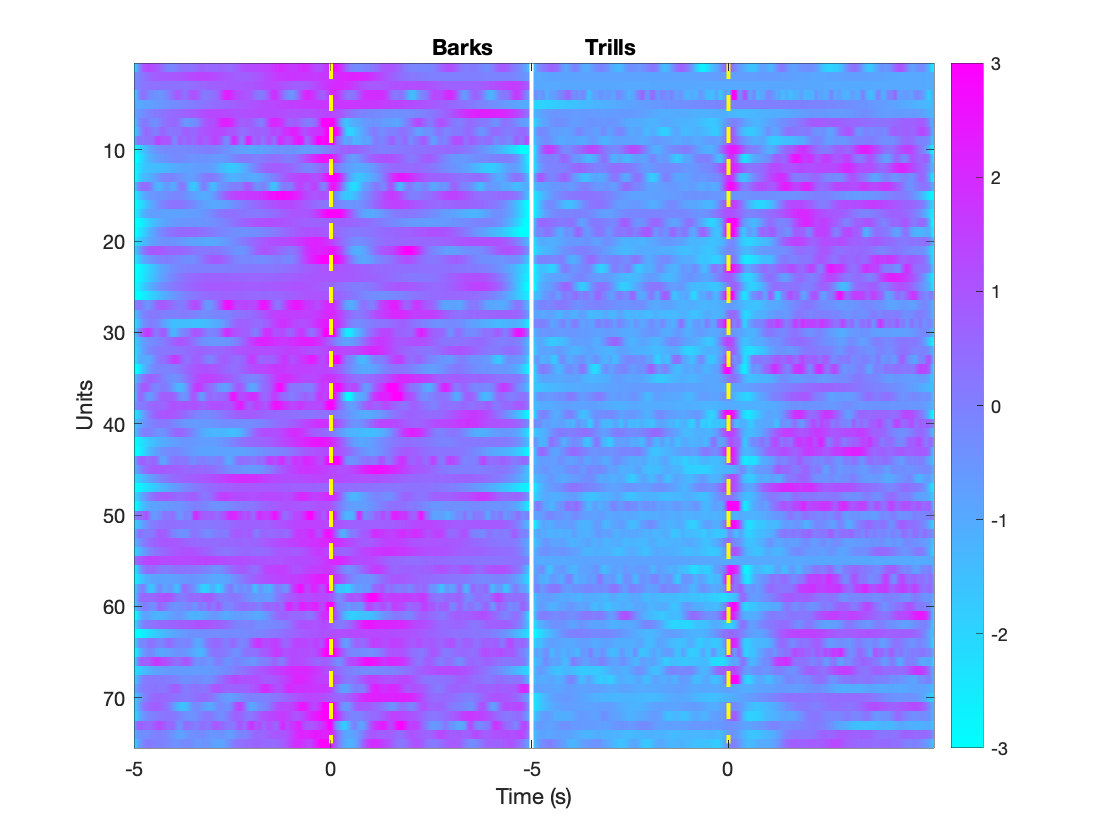

imagesc(KDE_onset_Mat_BaTr_ZS(T==Clust,:))
if CLim01
    caxis(CLim)
else
    CLim = caxis;
end
colorbar()
colormap('cool')
hold on
% delimiting Barks from Trills
line(TBa*ones(2,1), [-1 sum(T==Clust)+1],'Color', 'w', 'LineWidth',2)
hold on
% Barks onset
line([-Tstart -Tstart], [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
ylabel('Units')
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
title('Barks               Trills')
hold off

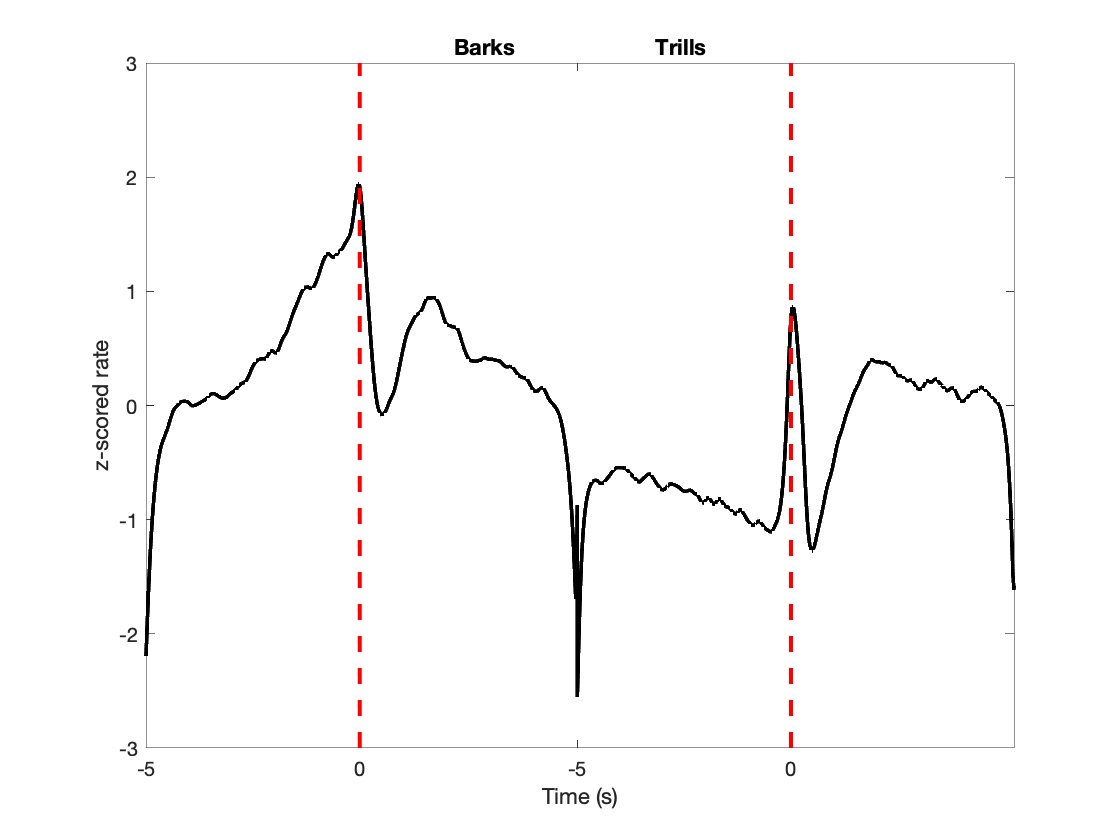


plot(mean(KDE_onset_Mat_BaTr_ZS(T==Clust,:)), 'k-', 'LineWidth',2)
xlim([0 size(KDE_onset_Mat_BaTr_ZS,2)])
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
hold on
% Barks onset
line([-Tstart -Tstart], CLim,'Color','r','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), CLim,'Color','r','LineStyle','--', 'LineWidth',2)
ylabel('z-scored rate')
title('Barks                       Trills')
hold off


% cluster 4
Clust=4;
IndSSU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSSU));
IndSMU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSMU));
fprintf(1,'**** Cluster %d *****\n%d units, %d single units, %d multi-units\n', Clust, sum(T==Clust),length(IndSSU),length(IndSMU))

**** Cluster 4 *****
129 units, 33 single units, 96 multi-units


for ii=1:length(IndSSU)
    fprintf('Single Unit: %s\n',ListSSU(IndSSU(ii)).name)
end

Single Unit: 59834_20190610_SSS_1-130.mat
Single Unit: 59834_20190611_SSS_1-117.mat
Single Unit: 59834_20190611_SSS_1-183.mat
Single Unit: 59834_20190611_SSS_1-97.mat
Single Unit: 59834_20190611_SSS_2-222.mat
Single Unit: 59834_20190612_SSS_1-81.mat
Single Unit: 59834_20190612_SSS_2-93.mat
Single Unit: 59834_20190613_SSS_1-11.mat
Single Unit: 59834_20190614_SSS_1-100.mat
Single Unit: 59834_20190616_SSS_1-77.mat
Single Unit: 59834_20190616_SSS_2-125.mat
Single Unit: 59834_20190617_SSS_2-167.mat
Single Unit: 59834_20190618_SSS_2-145.mat
Single Unit: 59834_20190618_SSS_2-160.mat
Single Unit: 59834_20190618_SSS_2-188.mat
Single Unit: 59834_20190619_SSS_2-120.mat
Single Unit: 59834_20190619_SSS_2-148.mat
Single Unit: 59834_20190619_SSS_4-222.mat
Single Unit: 59834_20190620_SSS_2-123.mat
Single Unit: 59834_20190620_SSS_2-215.mat
Single Unit: 59834_20190621_SSS_2-112.mat
Single Unit: 59834_20190621_SSS_2-124.mat
Single Unit: 59834_20190627_SSS_4-282.mat
Single Unit: 59834_20190628_SSS_4-216.m

for ii=1:length(IndSMU)
    fprintf('Multi Unit: %s\n',ListSSU(IndSMU(ii)).name)
end

Multi Unit: 59834_20190607_SSM_1-153.mat
Multi Unit: 59834_20190611_SSS_1-109.mat
Multi Unit: 59834_20190612_SSM_1-75.mat
Multi Unit: 59834_20190612_SSM_2-101.mat
Multi Unit: 59834_20190613_SSM_2-103.mat
Multi Unit: 59834_20190613_SSM_2-117.mat
Multi Unit: 59834_20190613_SSM_2-89.mat
Multi Unit: 59834_20190614_SSM_1-92.mat
Multi Unit: 59834_20190614_SSM_2-126.mat
Multi Unit: 59834_20190616_SSM_2-204.mat
Multi Unit: 59834_20190616_SSM_3-141.mat
Multi Unit: 59834_20190616_SSM_3-175.mat
Multi Unit: 59834_20190616_SSS_2-131.mat
Multi Unit: 59834_20190618_SSM_3-172.mat
Multi Unit: 59834_20190619_SSM_3-158.mat
Multi Unit: 59834_20190619_SSM_4-200.mat
Multi Unit: 59834_20190619_SSM_4-204.mat
Multi Unit: 59834_20190619_SSS_4-208.mat
Multi Unit: 59834_20190619_SSS_4-216.mat
Multi Unit: 59834_20190619_SSS_4-234.mat
Multi Unit: 59834_20190620_SSM_4-173.mat
Multi Unit: 59834_20190620_SSM_4-193.mat
Multi Unit: 59834_20190620_SSM_4-216.mat
Multi Unit: 59834_20190620_SSS_4-201.mat
Multi Unit: 59834_2

fprintf(1,' Plot ZS data Cluster %d \n', Clust)

 Plot ZS data Cluster 4 


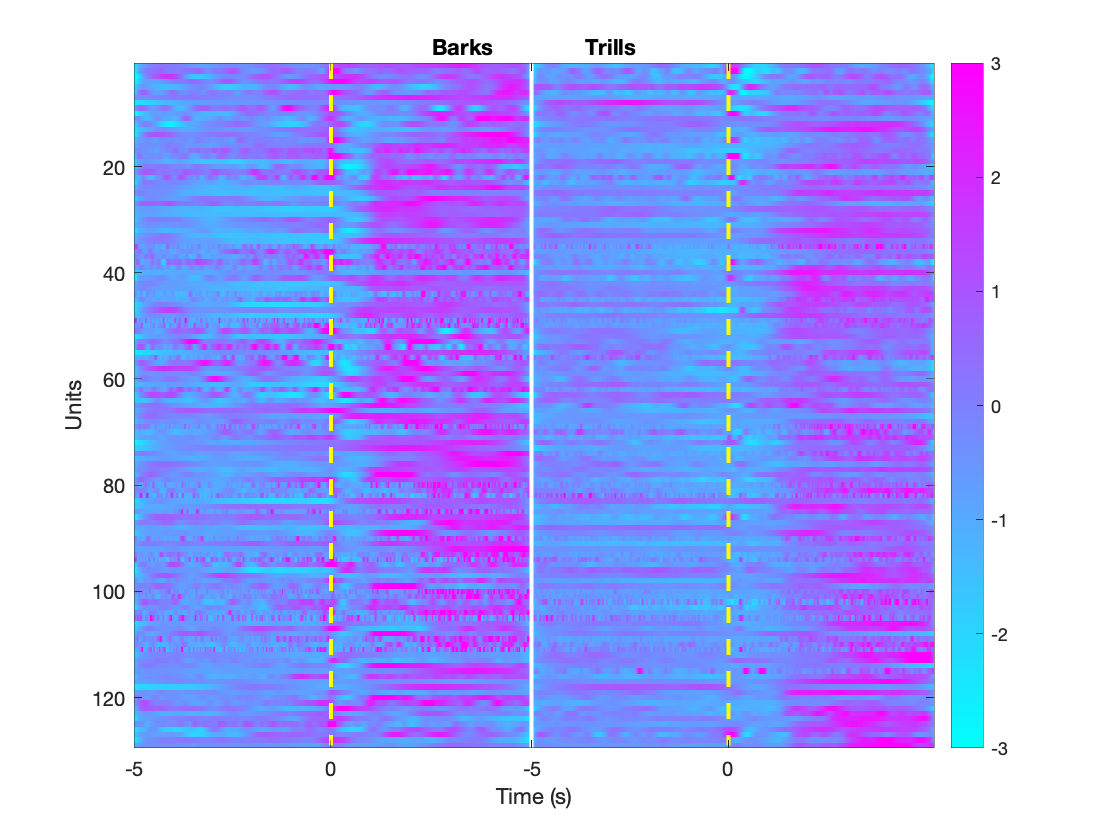

imagesc(KDE_onset_Mat_BaTr_ZS(T==Clust,:))
if CLim01
    caxis(CLim)
else
    CLim = caxis;
end
colorbar()
colormap('cool')
hold on
% delimiting Barks from Trills
line(TBa*ones(2,1), [-1 sum(T==Clust)+1],'Color', 'w', 'LineWidth',2)
hold on
% Barks onset
line([-Tstart -Tstart], [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
ylabel('Units')
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
title('Barks               Trills')
hold off

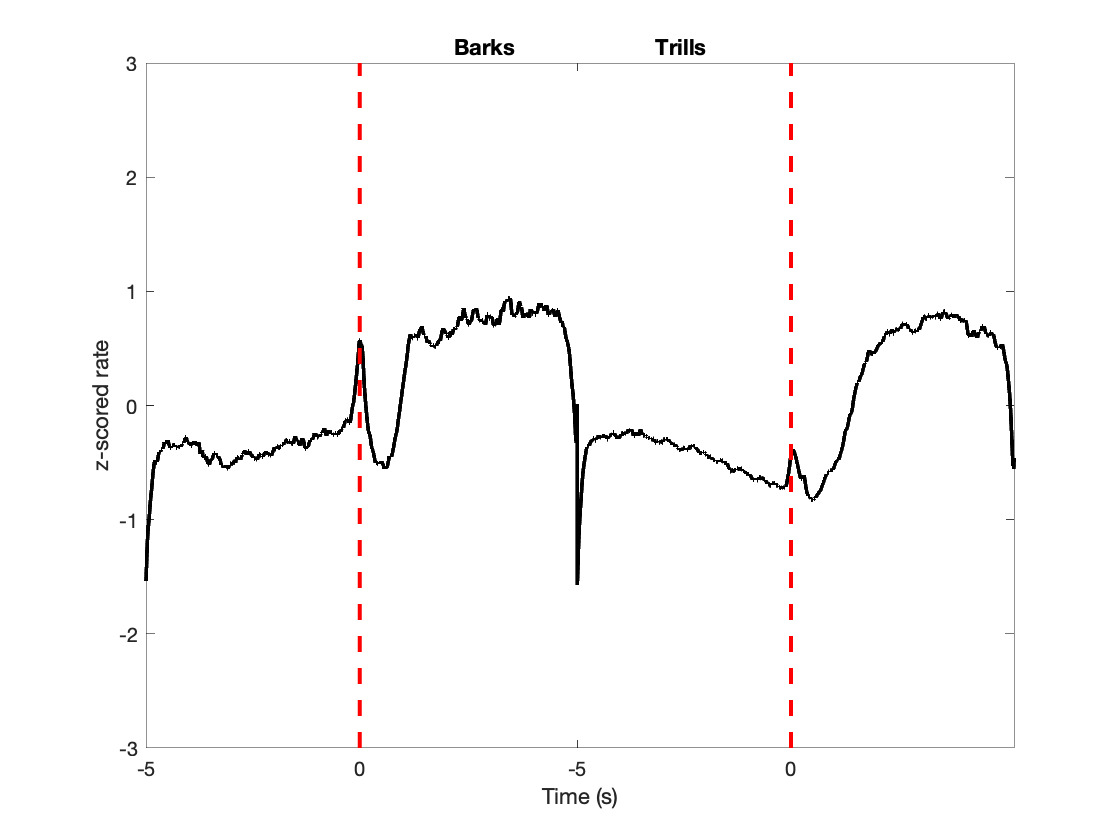


plot(mean(KDE_onset_Mat_BaTr_ZS(T==Clust,:)), 'k-', 'LineWidth',2)
xlim([0 size(KDE_onset_Mat_BaTr_ZS,2)])
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
hold on
% Barks onset
line([-Tstart -Tstart], CLim,'Color','r','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), CLim,'Color','r','LineStyle','--', 'LineWidth',2)
ylabel('z-scored rate')
title('Barks                       Trills')
hold off


% cluster 5
Clust=5;
IndSSU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSSU));
IndSMU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSMU));
fprintf(1,'**** Cluster %d *****\n%d units, %d single units, %d multi-units\n', Clust, sum(T==Clust),length(IndSSU),length(IndSMU))

**** Cluster 5 *****
101 units, 38 single units, 63 multi-units


for ii=1:length(IndSSU)
    fprintf('Single Unit: %s\n',ListSSU(IndSSU(ii)).name)
end

Single Unit: 59834_20190611_SSS_3-137.mat
Single Unit: 59834_20190611_SSS_3-181.mat
Single Unit: 59834_20190612_SSS_2-109.mat
Single Unit: 59834_20190612_SSS_3-191.mat
Single Unit: 59834_20190612_SSS_3-193.mat
Single Unit: 59834_20190612_SSS_3-22.mat
Single Unit: 59834_20190613_SSS_3-127.mat
Single Unit: 59834_20190613_SSS_3-141.mat
Single Unit: 59834_20190614_SSS_3-190.mat
Single Unit: 59834_20190616_SSS_3-137.mat
Single Unit: 59834_20190617_SSS_3-155.mat
Single Unit: 59834_20190618_SSS_3-168.mat
Single Unit: 59834_20190619_SSS_3-154.mat
Single Unit: 59834_20190620_SSS_3-131.mat
Single Unit: 59834_20190621_SSS_3-168.mat
Single Unit: 59834_20190622_SSS_3-152.mat
Single Unit: 59834_20190623_SSS_3-222.mat
Single Unit: 59834_20190623_SSS_3-223.mat
Single Unit: 59834_20190626_SSS_1-87.mat
Single Unit: 59834_20190626_SSS_3-173.mat
Single Unit: 59834_20190627_SSS_1-72.mat
Single Unit: 59834_20190627_SSS_3-323.mat
Single Unit: 59834_20190628_SSS_1-98.mat
Single Unit: 59834_20190628_SSS_3-178.

for ii=1:length(IndSMU)
    fprintf('Multi Unit: %s\n',ListSSU(IndSMU(ii)).name)
end

Multi Unit: 59834_20190607_SSM_2-175.mat
Multi Unit: 59834_20190607_SSM_2-183.mat
Multi Unit: 59834_20190607_SSM_2-201.mat
Multi Unit: 59834_20190611_SSM_3-186.mat
Multi Unit: 59834_20190612_SSS_3-157.mat
Multi Unit: 59834_20190612_SSS_3-165.mat
Multi Unit: 59834_20190612_SSS_3-169.mat
Multi Unit: 59834_20190613_SSM_3-123.mat
Multi Unit: 59834_20190613_SSM_3-147.mat
Multi Unit: 59834_20190614_SSM_2-140.mat
Multi Unit: 59834_20190614_SSM_3-162.mat
Multi Unit: 59834_20190614_SSM_3-184.mat
Multi Unit: 59834_20190616_SSM_2-212.mat
Multi Unit: 59834_20190616_SSM_3-171.mat
Multi Unit: 59834_20190616_SSM_3-201.mat
Multi Unit: 59834_20190616_SSS_1-73.mat
Multi Unit: 59834_20190616_SSS_3-149.mat
Multi Unit: 59834_20190618_SSM_2-121.mat
Multi Unit: 59834_20190618_SSM_3-184.mat
Multi Unit: 59834_20190619_SSM_2-144.mat
Multi Unit: 59834_20190619_SSM_3-166.mat
Multi Unit: 59834_20190620_SSM_3-141.mat
Multi Unit: 59834_20190620_SSM_4-161.mat
Multi Unit: 59834_20190621_SSM_3-138.mat
Multi Unit: 59834

fprintf(1,' Plot ZS data Cluster %d \n', Clust)

 Plot ZS data Cluster 5 


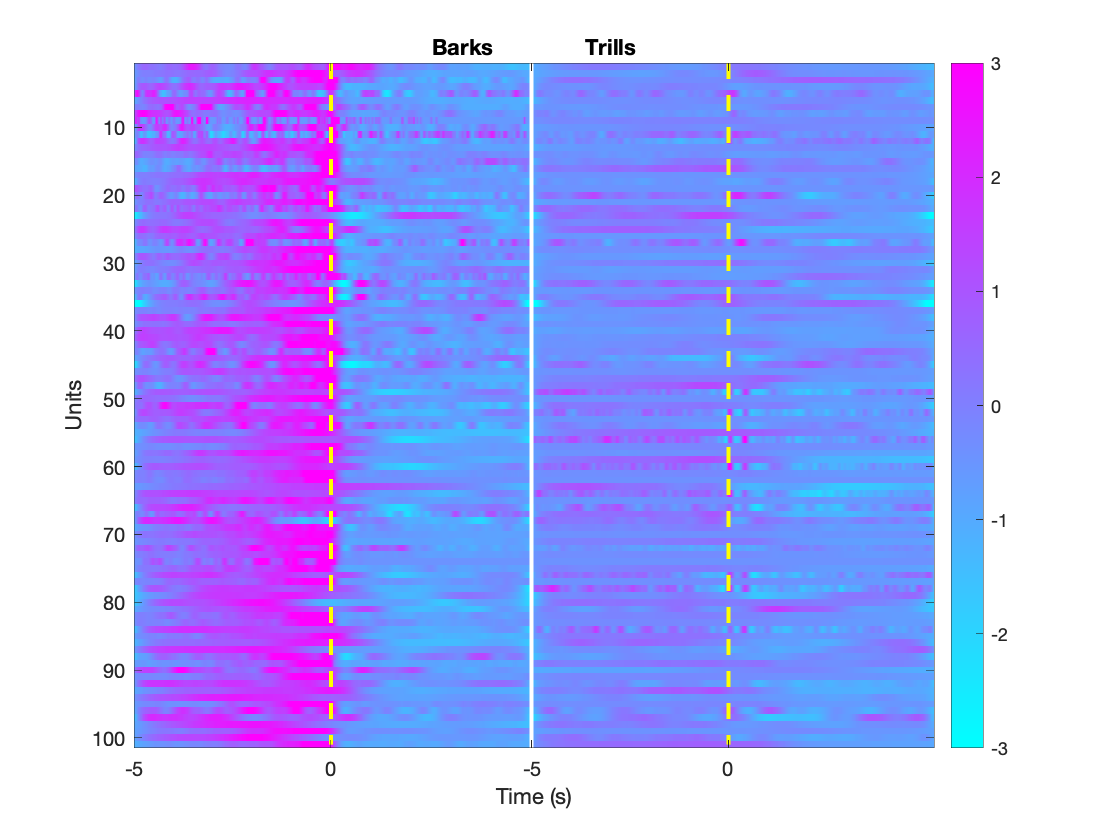

imagesc(KDE_onset_Mat_BaTr_ZS(T==Clust,:))
if CLim01
    caxis(CLim)
else
    CLim = caxis;
end
colorbar()
colormap('cool')
hold on
% delimiting Barks from Trills
line(TBa*ones(2,1), [-1 sum(T==Clust)+1],'Color', 'w', 'LineWidth',2)
hold on
% Barks onset
line([-Tstart -Tstart], [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
ylabel('Units')
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
title('Barks               Trills')
hold off

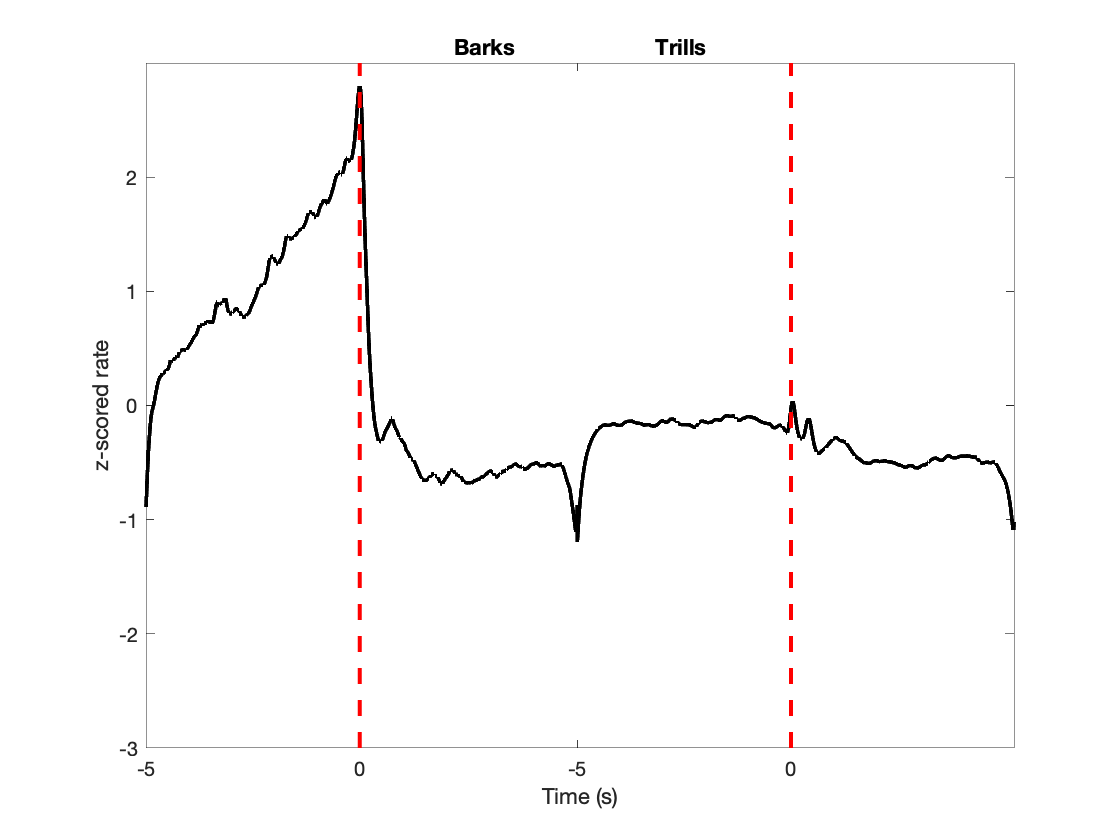


plot(mean(KDE_onset_Mat_BaTr_ZS(T==Clust,:)), 'k-', 'LineWidth',2)
xlim([0 size(KDE_onset_Mat_BaTr_ZS,2)])
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
hold on
% Barks onset
line([-Tstart -Tstart], CLim,'Color','r','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), CLim,'Color','r','LineStyle','--', 'LineWidth',2)
ylabel('z-scored rate')
title('Barks                       Trills')
hold off

save('explore_populationSU_data_5000.mat')

## Hierarchical clustering on KDE onset of all cells for Ba and Tr starting at -200ms and ending at 500ms

% gather the data
Tstart = -200;
Tstop = 500;
GoodCellIndices = sort([find(SSSU); find(SSMU)]);
GC = length(GoodCellIndices);
KDE_onset = cell(GC,3);
T_onset = cell(GC,2);
Tmax = nan(GC,2);
MeanKDEBaTr = nan(GC,1);
StdKDEBaTr = nan(GC,1);
MeanKDEAllVoc = nan(GC,1);
StdKDEAllVoc = nan(GC,1);
for ss=1:GC
    fprintf(1,'File %d/%d\n',ss,GC)
    [~,FileName] = fileparts(ListSSU(GoodCellIndices(ss)).name);
    Data=load(fullfile(ListSSU(GoodCellIndices(ss)).folder,ListSSU(GoodCellIndices(ss)).name));
    if isfield(Data,'KDE_onset') && isfield(Data.KDE_onset, 'SelfBaOp')
        Tmax(ss,1) = max(Data.KDE_onset.SelfBaOp(2,:));
        KDE_onset{ss,1} = Data.KDE_onset.SelfBaOp(1,find(Data.KDE_onset.SelfBaOp(2,:)==Tstart):find(Data.KDE_onset.SelfBaOp(2,:)==Tstop));
    end
    if isfield(Data,'KDE_onset') && isfield(Data.KDE_onset, 'SelfTrOp')
        Tmax(ss,2) = max(Data.KDE_onset.SelfTrOp(2,:));
        KDE_onset{ss,2} = Data.KDE_onset.SelfTrOp(1,find(Data.KDE_onset.SelfTrOp(2,:)==Tstart):find(Data.KDE_onset.SelfTrOp(2,:)==Tstop));
    end
    if isfield(Data,'KDE_onset') && isfield(Data.KDE_onset, 'SelfVocOp')
        KDE_onset{ss,3} = Data.KDE_onset.SelfVocOp(1,find(Data.KDE_onset.SelfVocOp(2,:)==Tstart):find(Data.KDE_onset.SelfVocOp(2,:)==Tstop));
        MeanKDEAllVoc(ss) = nanmean(KDE_onset{ss,3}); 
        StdKDEAllVoc(ss) = nanstd(KDE_onset{ss,3}); 
    end
    MeanKDEBaTr(ss) = nanmean([KDE_onset{ss,1} KDE_onset{ss,2}]); 
    StdKDEBaTr(ss) = nanstd([KDE_onset{ss,1} KDE_onset{ss,2}]); 
end

File 1/486
File 2/486
File 3/486
File 4/486
File 5/486
File 6/486
File 7/486
File 8/486
File 9/486
File 10/486
File 11/486
File 12/486
File 13/486
File 14/486
File 15/486
File 16/486
File 17/486
File 18/486
File 19/486
File 20/486
File 21/486
File 22/486
File 23/486
File 24/486
File 25/486
File 26/486
File 27/486
File 28/486
File 29/486
File 30/486
File 31/486
File 32/486
File 33/486
File 34/486
File 35/486
File 36/486
File 37/486
File 38/486
File 39/486
File 40/486
File 41/486
File 42/486
File 43/486
File 44/486
File 45/486
File 46/486
File 47/486
File 48/486
File 49/486
File 50/486
File 51/486
File 52/486
File 53/486
File 54/486
File 55/486
File 56/486
File 57/486
File 58/486
File 59/486
File 60/486
File 61/486
File 62/486
File 63/486
File 64/486
File 65/486
File 66/486
File 67/486
File 68/486
File 69/486
File 70/486
File 71/486
File 72/486
File 73/486
File 74/486
File 75/486
File 76/486
File 77/486
File 78/486
File 79/486
File 80/486
File 81/486
File 82/486
File 83/486
File 84/486
F

save('explore_populationSU_data_200.mat')

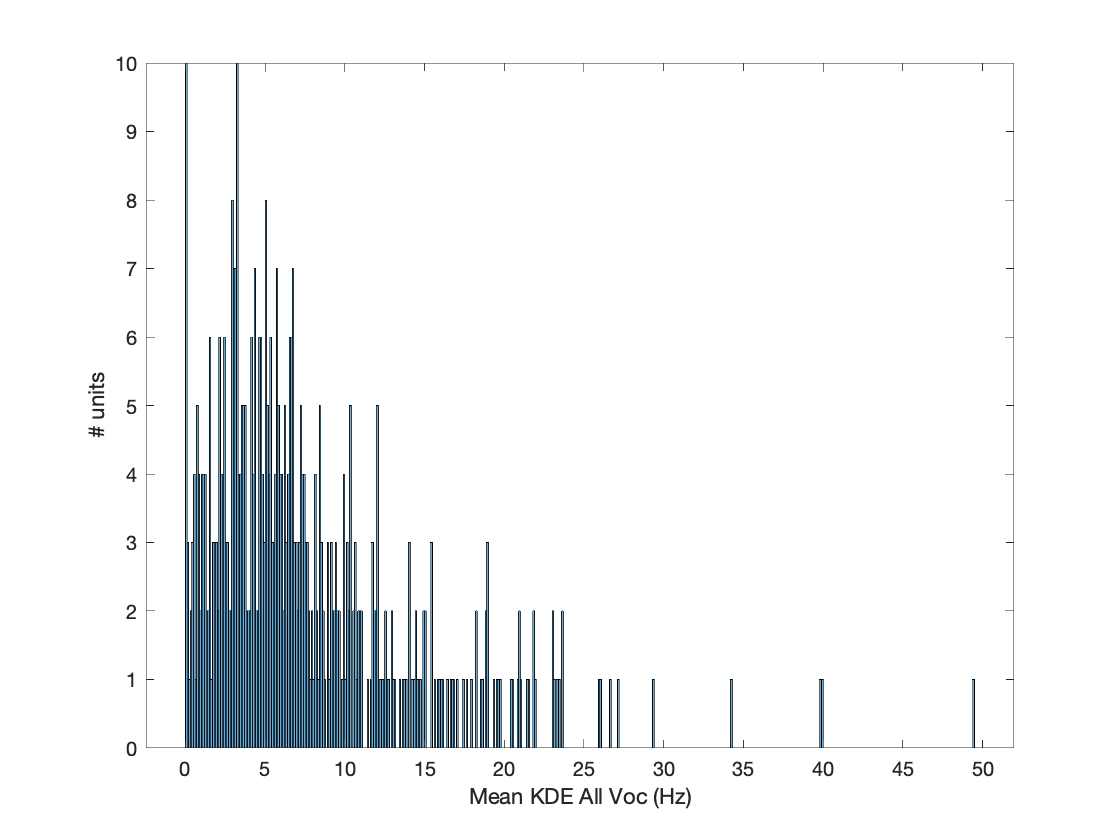

% Explore the average spike rates and get rid of non active cells?
histogram(MeanKDEAllVoc,'BinWidth',0.1)
xlabel('Mean KDE All Voc (Hz)')
ylabel('# units')

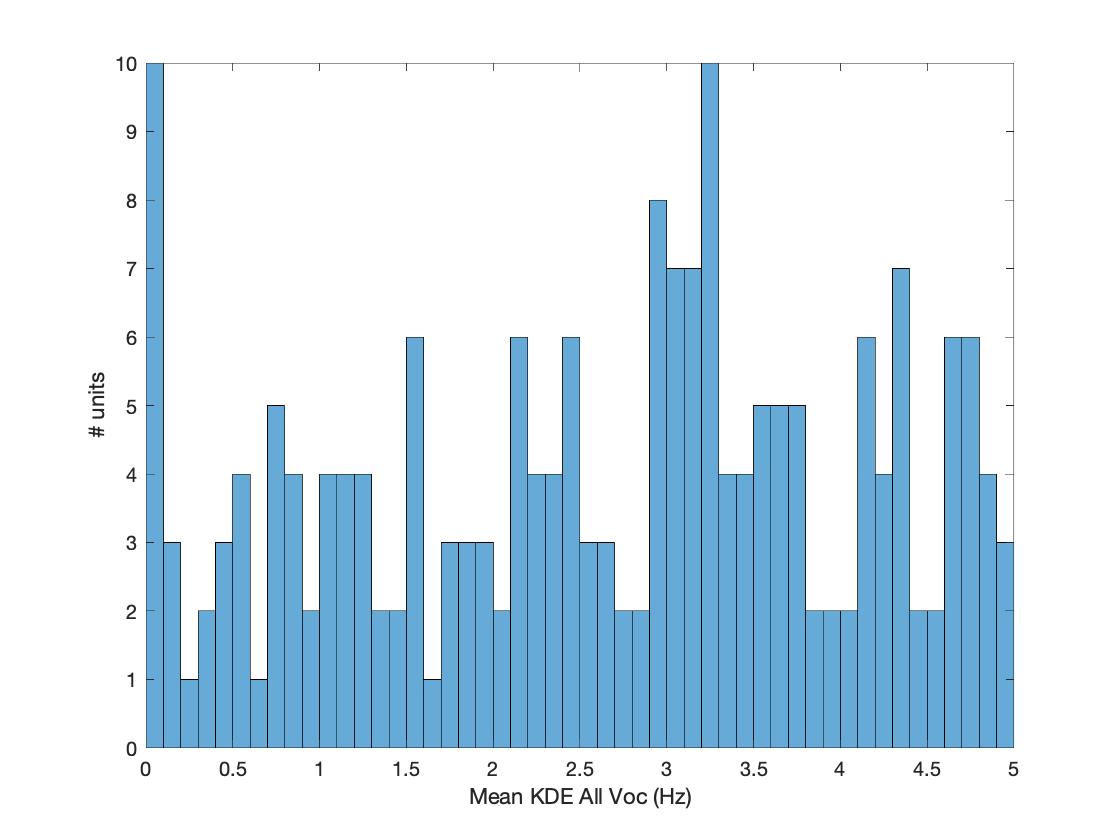

histogram(MeanKDEAllVoc,'BinWidth',0.1)
xlabel('Mean KDE All Voc (Hz)')
ylabel('# units')
xlim([0 5])

ActiveCells = find(MeanKDEAllVoc>0.1);
fprintf(1,'Number of active cells: %d',length(ActiveCells))

Number of active cells: 476

% Trim the data of active cells in time and create a matrix of all the z-scored KDE

BaTr_0ind = ~isnan(Tmax(:,1)) .* ~isnan(Tmax(:,2)).* ~isnan(MeanKDEBaTr).*MeanKDEAllVoc>0.1;
BaTr_Ind = find(BaTr_0ind);
fprintf('The clustering algorithm can be performed on the data of %d/%d\n',sum(BaTr_0ind),length(ActiveCells))

The clustering algorithm can be performed on the data of 397/476


TBa = length(Tstart:Tstop);
TTr = length(Tstart:Tstop);
KDE_onset_Mat_BaTr_ZS_noTrim = nan(sum(BaTr_0ind),TBa + TTr);
for ss=1:sum(BaTr_0ind)
    fprintf(1,'File %d/%d\n',ss,sum(BaTr_0ind))
    KDE_onset_Mat_BaTr_ZS_noTrim(ss,:) = ([KDE_onset{BaTr_Ind(ss),1}(1:TBa) KDE_onset{BaTr_Ind(ss),2}(1:TTr)]-MeanKDEBaTr(BaTr_Ind(ss)))/StdKDEBaTr(BaTr_Ind(ss));
end

File 1/397
File 2/397
File 3/397
File 4/397
File 5/397
File 6/397
File 7/397
File 8/397
File 9/397
File 10/397
File 11/397
File 12/397
File 13/397
File 14/397
File 15/397
File 16/397
File 17/397
File 18/397
File 19/397
File 20/397
File 21/397
File 22/397
File 23/397
File 24/397
File 25/397
File 26/397
File 27/397
File 28/397
File 29/397
File 30/397
File 31/397
File 32/397
File 33/397
File 34/397
File 35/397
File 36/397
File 37/397
File 38/397
File 39/397
File 40/397
File 41/397
File 42/397
File 43/397
File 44/397
File 45/397
File 46/397
File 47/397
File 48/397
File 49/397
File 50/397
File 51/397
File 52/397
File 53/397
File 54/397
File 55/397
File 56/397
File 57/397
File 58/397
File 59/397
File 60/397
File 61/397
File 62/397
File 63/397
File 64/397
File 65/397
File 66/397
File 67/397
File 68/397
File 69/397
File 70/397
File 71/397
File 72/397
File 73/397
File 74/397
File 75/397
File 76/397
File 77/397
File 78/397
File 79/397
File 80/397
File 81/397
File 82/397
File 83/397
File 84/397
F

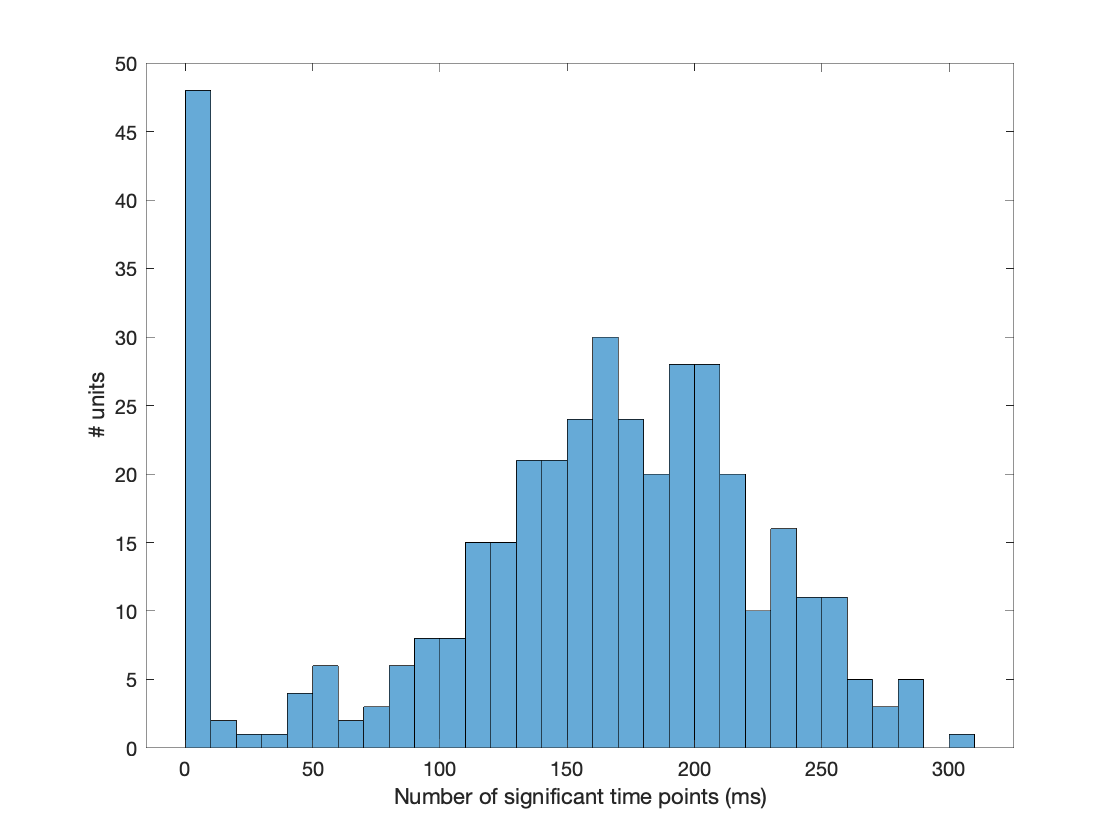

% Explore the number of time points with signficant (zscore>2) difference
% in spike rate
SignifTP = sum(abs(KDE_onset_Mat_BaTr_ZS_noTrim)>1.6,2);
histogram(SignifTP, 'BinWidth',10)
xlabel('Number of significant time points (ms)')
ylabel('# units')

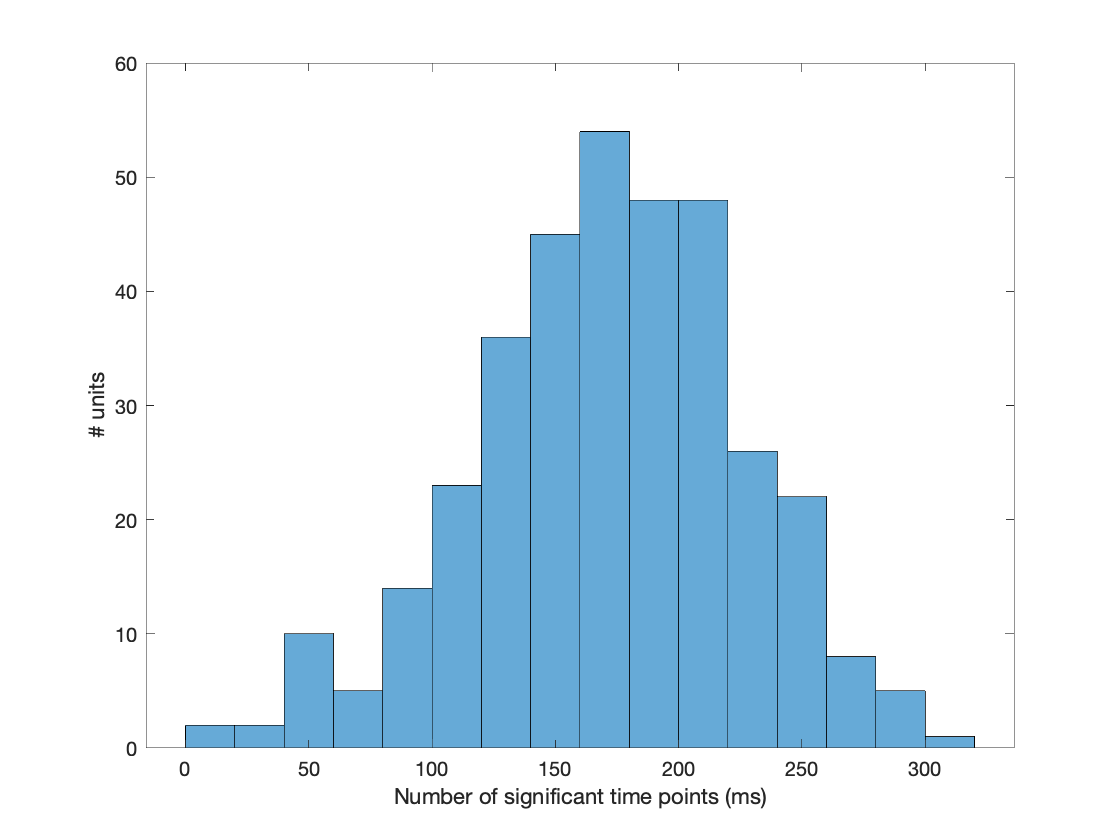

histogram(SignifTP(logical(SignifTP)), 'BinWidth',20)
xlabel('Number of significant time points (ms)')
ylabel('# units')

fprintf(1,'%d/%d (%.2f %%) units are significant\n',sum(logical(SignifTP)),length(SignifTP),100*sum(logical(SignifTP))/length(SignifTP))

349/397 (87.91 %) units are significant


fprintf(1, 'Duration of significance: %.1f +/- %.1f ms\n',mean(SignifTP(logical(SignifTP))), std(SignifTP(logical(SignifTP)))/(sum(logical(SignifTP)))^0.5)

Duration of significance: 171.1 +/- 2.9 ms


fprintf(1,'Minimum value %.1f ms\n',min(SignifTP(logical(SignifTP))))

Minimum value 10.0 ms


fprintf(1, 'Maximum value %.1f ms\n',max(SignifTP(logical(SignifTP))))

Maximum value 301.0 ms


ListSSUGC = ListSSU(GoodCellIndices);
ListSSUGCBaTr = ListSSUGC(BaTr_Ind);
NonSignif=find(~logical(SignifTP));
fprintf(1,'***** Checking non-significant cells ******')
figure;
for ii=1:length(NonSignif)
    clc
    set(gcf, 'Visible','on')
    fprintf(1,ListSSUGCBaTr(NonSignif(ii)).name)
    plot(KDE_onset_Mat_BaTr_ZS(NonSignif(ii),:))
    title(sprintf('%s',ListSSUGCBaTr(NonSignif(ii)).name))
    pause()
end

% Restrict the dataset to significant cells
KDE_onset_Mat_BaTr_ZS = KDE_onset_Mat_BaTr_ZS_noTrim(logical(SignifTP),:);
BaTr_ind = BaTr_Ind(logical(SignifTP));

% Clustering based on zscored KDE
Z = linkage(KDE_onset_Mat_BaTr_ZS,'ward','euclidean')

Z =   156.0000  169.0000    0.7013
  125.0000  350.0000    0.7531
  317.0000  328.0000    1.6892
   62.0000  188.0000    2.0743
  137.0000  351.0000    2.0957
  112.0000  219.0000    2.2428
   56.0000   70.0000    2.2894
  252.0000  267.0000    2.3193
  157.0000  281.0000    2.6760
   72.0000  268.0000    3.0258


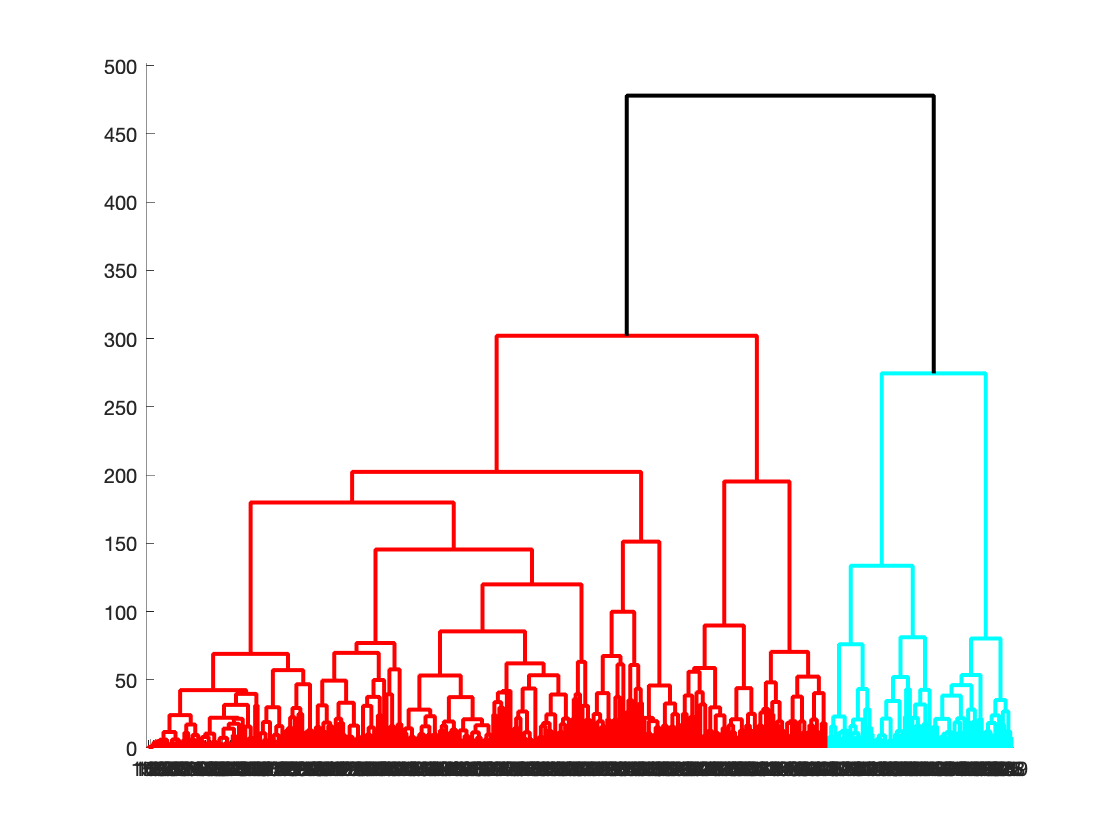

D1 = dendrogram(Z,0, 'ColorThreshold','Default');
set(D1,'LineWidth',2)

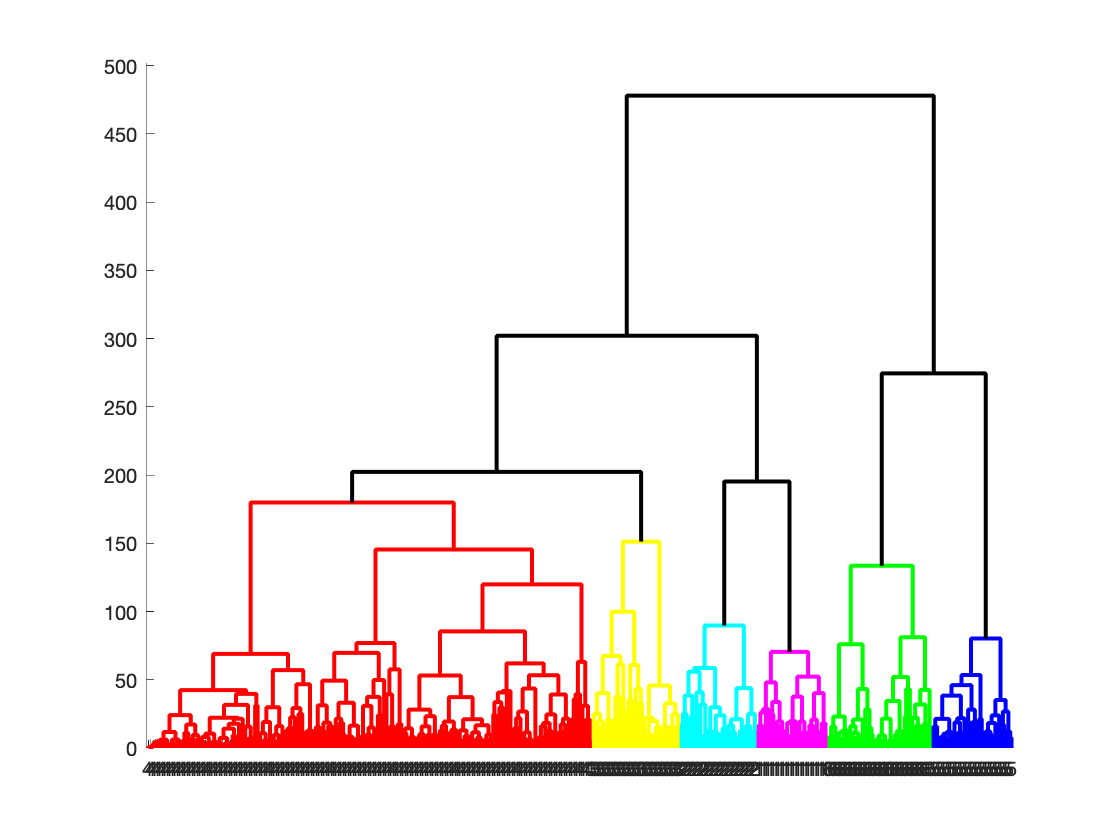

T = cluster(Z,'maxclust',6);
cutoff = median([Z(end-5,3) Z(end-4,3)]);
D2=dendrogram(Z,0,'ColorThreshold',cutoff,'Labels',num2str(T));
set(D2, 'LineWidth',2)

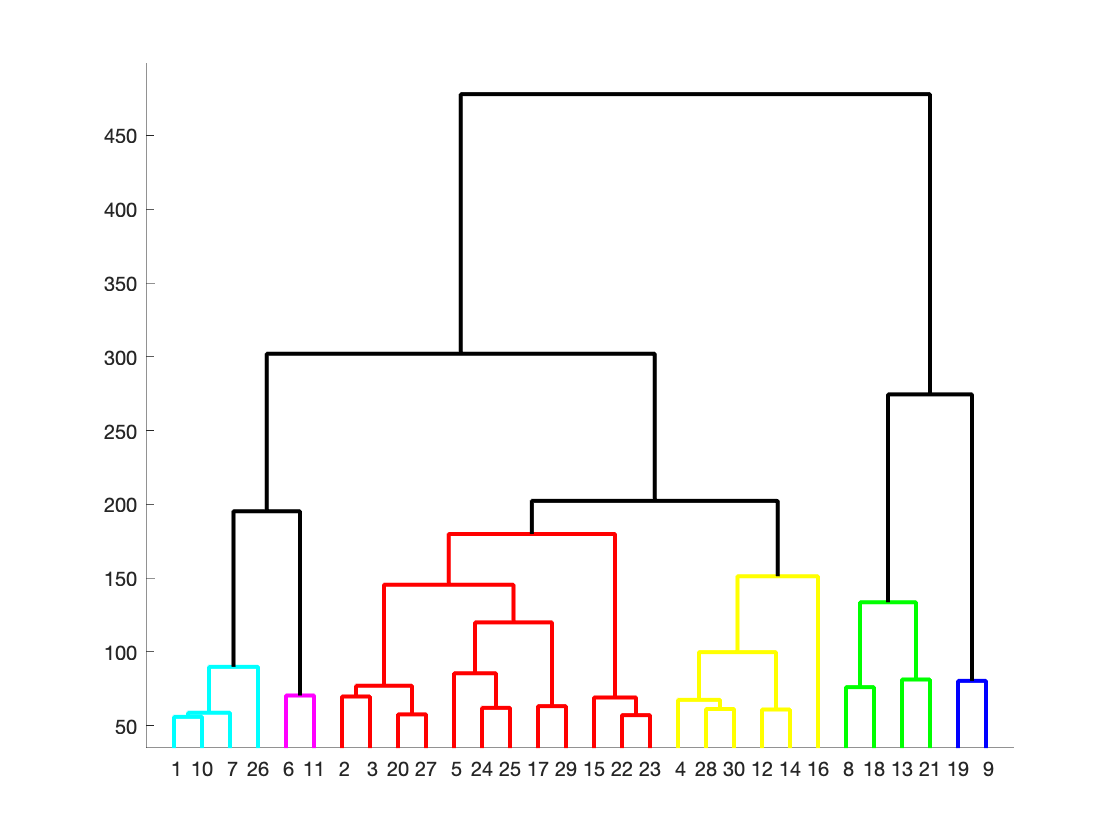

D3=dendrogram(Z,30,'ColorThreshold',cutoff,'Labels',num2str(T));
set(D3, 'LineWidth',2)

Plot the average spike rate for each cluster

CLim01 = 1;
if CLim01
    CLim = [-3 3];
end
% cluster 1
Clust=1;
IndSSU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSSU));
IndSMU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSMU));
fprintf(1,'**** Cluster %d *****\n%d units, %d single units, %d multi-units\n', Clust, sum(T==Clust),length(IndSSU),length(IndSMU))

**** Cluster 1 *****
28 units, 4 single units, 24 multi-units


for ii=1:length(IndSSU)
    fprintf('Single Unit: %s\n',ListSSU(IndSSU(ii)).name)
end

Single Unit: 59834_20190611_SSS_3-137.mat
Single Unit: 59834_20190621_SSM_3-167.mat
Single Unit: 59834_20190626_SSS_3-201.mat
Single Unit: 59834_20190702_SSM_2-246.mat


for ii=1:length(IndSMU)
    fprintf('Multi Unit: %s\n',ListSSU(IndSMU(ii)).name)
end

Multi Unit: 59834_20190610_SSM_1-143.mat
Multi Unit: 59834_20190614_SSM_3-184.mat
Multi Unit: 59834_20190614_SSS_3-180.mat
Multi Unit: 59834_20190616_SSM_2-204.mat
Multi Unit: 59834_20190616_SSM_3-141.mat
Multi Unit: 59834_20190616_SSM_3-171.mat
Multi Unit: 59834_20190618_SSM_3-172.mat
Multi Unit: 59834_20190619_SSM_1-72.mat
Multi Unit: 59834_20190619_SSM_1-98.mat
Multi Unit: 59834_20190619_SSM_3-166.mat
Multi Unit: 59834_20190619_SSM_4-204.mat
Multi Unit: 59834_20190620_SSM_1-77.mat
Multi Unit: 59834_20190620_SSM_3-141.mat
Multi Unit: 59834_20190620_SSM_3-145.mat
Multi Unit: 59834_20190620_SSM_4-193.mat
Multi Unit: 59834_20190623_SSM_3-174.mat
Multi Unit: 59834_20190626_SSM_3-195.mat
Multi Unit: 59834_20190629_SSM_3-207.mat
Multi Unit: 59834_20190701_SSM_3-235.mat
Multi Unit: 59834_20190702_SSM_3-181.mat
Multi Unit: 59834_20190705_SSM_3-201.mat
Multi Unit: 59834_20190706_SSM_3-218.mat
Multi Unit: 59834_20190707_SSM_3-227.mat
Multi Unit: 59834_20190711_SSM_1-267.mat


fprintf(1,' Plot ZS data Cluster %d \n', Clust)

 Plot ZS data Cluster 1 


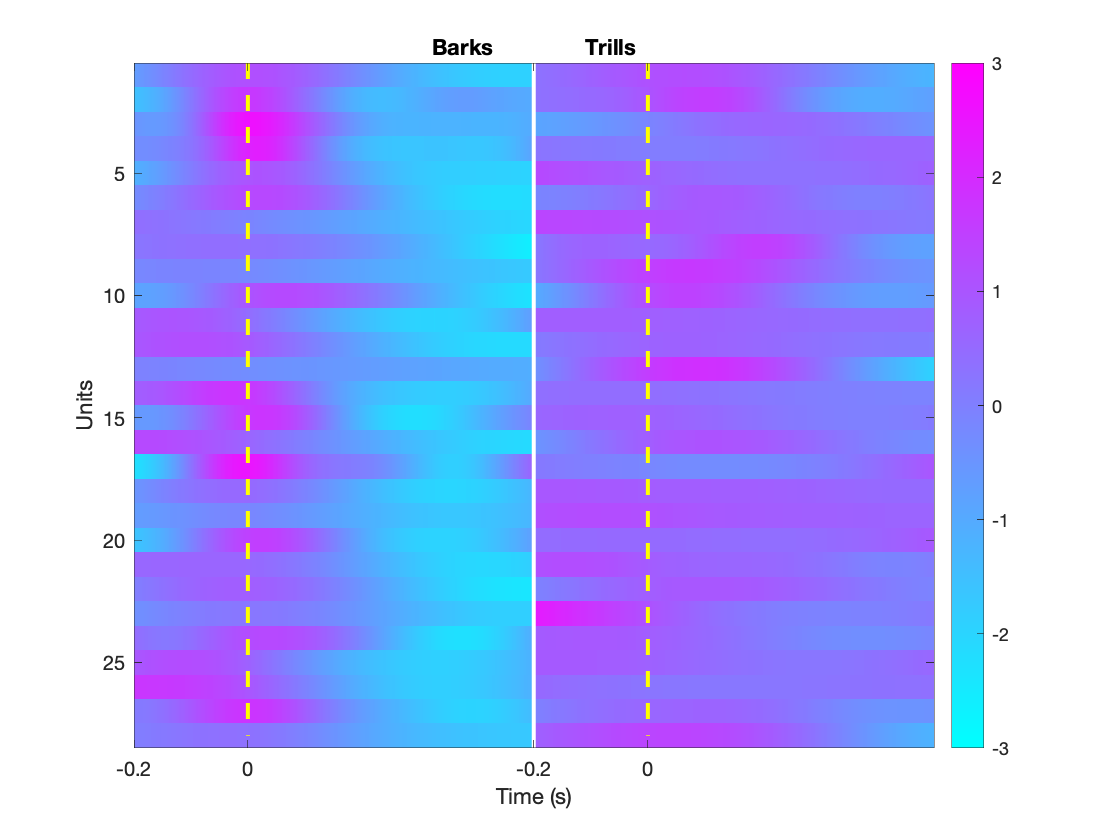

imagesc(KDE_onset_Mat_BaTr_ZS(T==Clust,:))
if CLim01
    caxis(CLim)
else
    CLim = caxis;
end
colorbar()
colormap('cool')
hold on
% delimiting Barks from Trills
line(TBa*ones(2,1), [-1 sum(T==Clust)+1],'Color', 'w', 'LineWidth',2)
hold on
% Barks onset
line([-Tstart -Tstart], [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
ylabel('Units')
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
title('Barks               Trills')
hold off

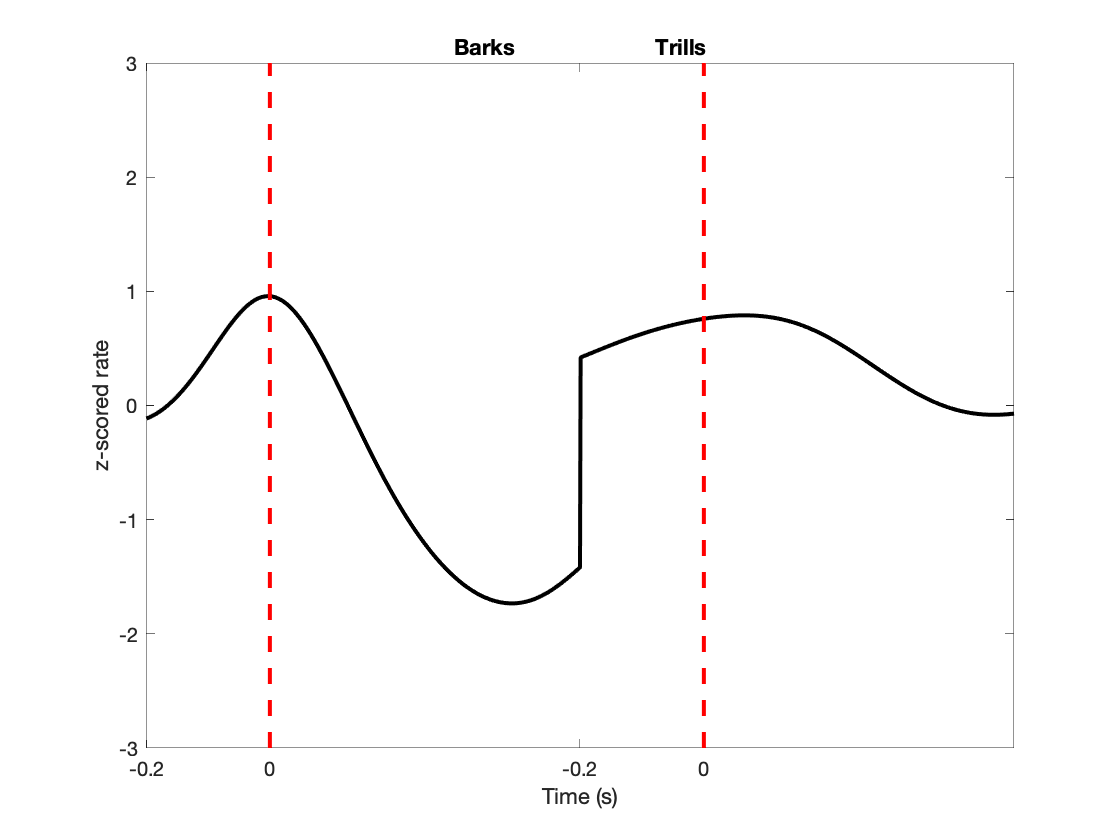


plot(mean(KDE_onset_Mat_BaTr_ZS(T==Clust,:)), 'k-', 'LineWidth',2)
xlim([0 size(KDE_onset_Mat_BaTr_ZS,2)])
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
hold on
% Barks onset
line([-Tstart -Tstart], CLim,'Color','r','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), CLim,'Color','r','LineStyle','--', 'LineWidth',2)
ylabel('z-scored rate')
title('Barks                       Trills')
hold off



% cluster 2 good example: 0612_SSS_1-81
Clust=2;
IndSSU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSSU));
IndSMU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSMU));
fprintf(1,'**** Cluster %d *****\n%d units, %d single units, %d multi-units\n', Clust, sum(T==Clust),length(IndSSU),length(IndSMU))

**** Cluster 2 *****
31 units, 5 single units, 26 multi-units


for ii=1:length(IndSSU)
    fprintf('Single Unit: %s\n',ListSSU(IndSSU(ii)).name)
end

Single Unit: 59834_20190610_SSS_1-130.mat
Single Unit: 59834_20190611_SSS_1-97.mat
Single Unit: 59834_20190612_SSS_1-81.mat
Single Unit: 59834_20190613_SSS_1-11.mat
Single Unit: 59834_20190614_SSS_1-100.mat


for ii=1:length(IndSMU)
    fprintf('Multi Unit: %s\n',ListSSU(IndSMU(ii)).name)
end

Multi Unit: 59834_20190607_SSM_1-153.mat
Multi Unit: 59834_20190611_SSM_3-190.mat
Multi Unit: 59834_20190619_SSS_4-234.mat
Multi Unit: 59834_20190620_SSM_4-216.mat
Multi Unit: 59834_20190621_SSM_1-84.mat
Multi Unit: 59834_20190621_SSM_1-92.mat
Multi Unit: 59834_20190623_SSM_1-104.mat
Multi Unit: 59834_20190623_SSM_1-227.mat
Multi Unit: 59834_20190623_SSM_1-94.mat
Multi Unit: 59834_20190627_SSM_1-104.mat
Multi Unit: 59834_20190628_SSM_1-108.mat
Multi Unit: 59834_20190628_SSM_1-84.mat
Multi Unit: 59834_20190629_SSM_1-105.mat
Multi Unit: 59834_20190629_SSM_1-119.mat
Multi Unit: 59834_20190630_SSM_1-219.mat
Multi Unit: 59834_20190701_SSM_1-287.mat
Multi Unit: 59834_20190701_SSM_1-288.mat
Multi Unit: 59834_20190702_SSM_1-67.mat
Multi Unit: 59834_20190704_SSM_1-84.mat
Multi Unit: 59834_20190705_SSM_1-265.mat
Multi Unit: 59834_20190706_SSM_1-303.mat
Multi Unit: 59834_20190706_SSM_1-304.mat
Multi Unit: 59834_20190707_SSM_1-262.mat
Multi Unit: 59834_20190710_SSM_1-100.mat
Multi Unit: 59834_2019

fprintf(1,' Plot ZS data Cluster %d \n', Clust)

 Plot ZS data Cluster 2 


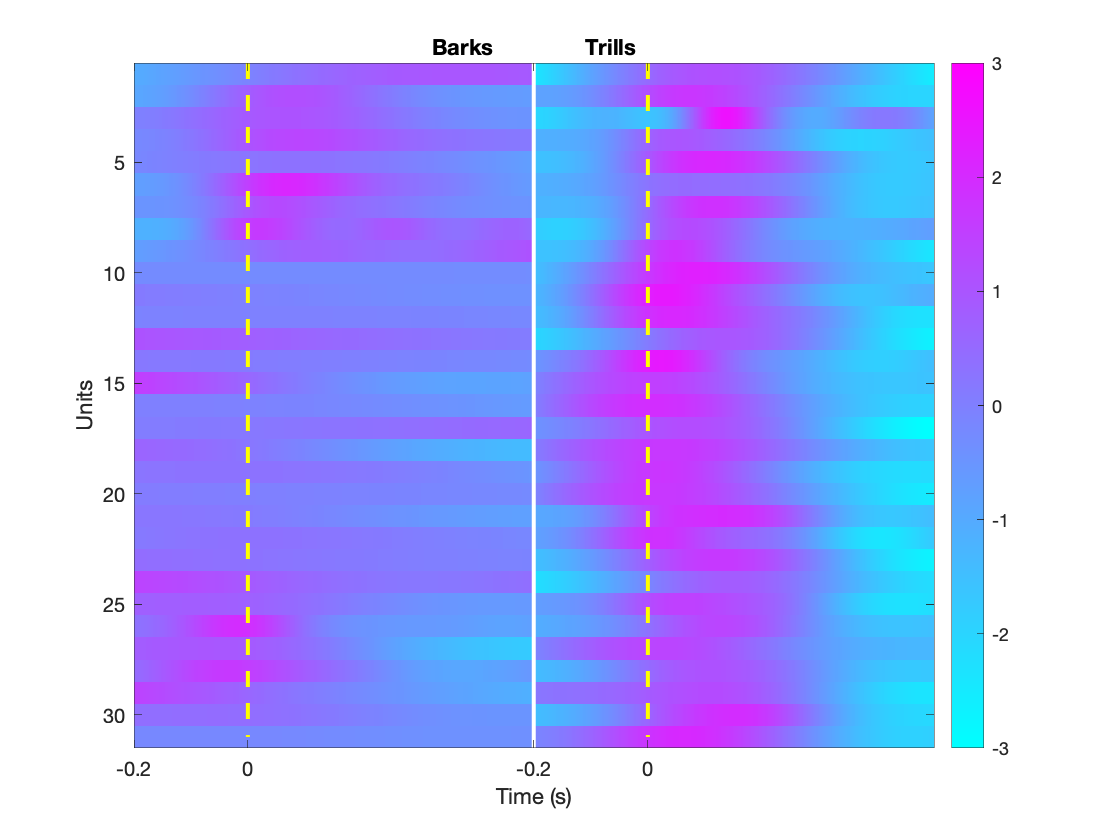

imagesc(KDE_onset_Mat_BaTr_ZS(T==Clust,:))
if CLim01
    caxis(CLim)
else
    CLim = caxis;
end
colorbar()
colormap('cool')
hold on
% delimiting Barks from Trills
line(TBa*ones(2,1), [-1 sum(T==Clust)+1],'Color', 'w', 'LineWidth',2)
hold on
% Barks onset
line([-Tstart -Tstart], [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
ylabel('Units')
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
title('Barks               Trills')
hold off

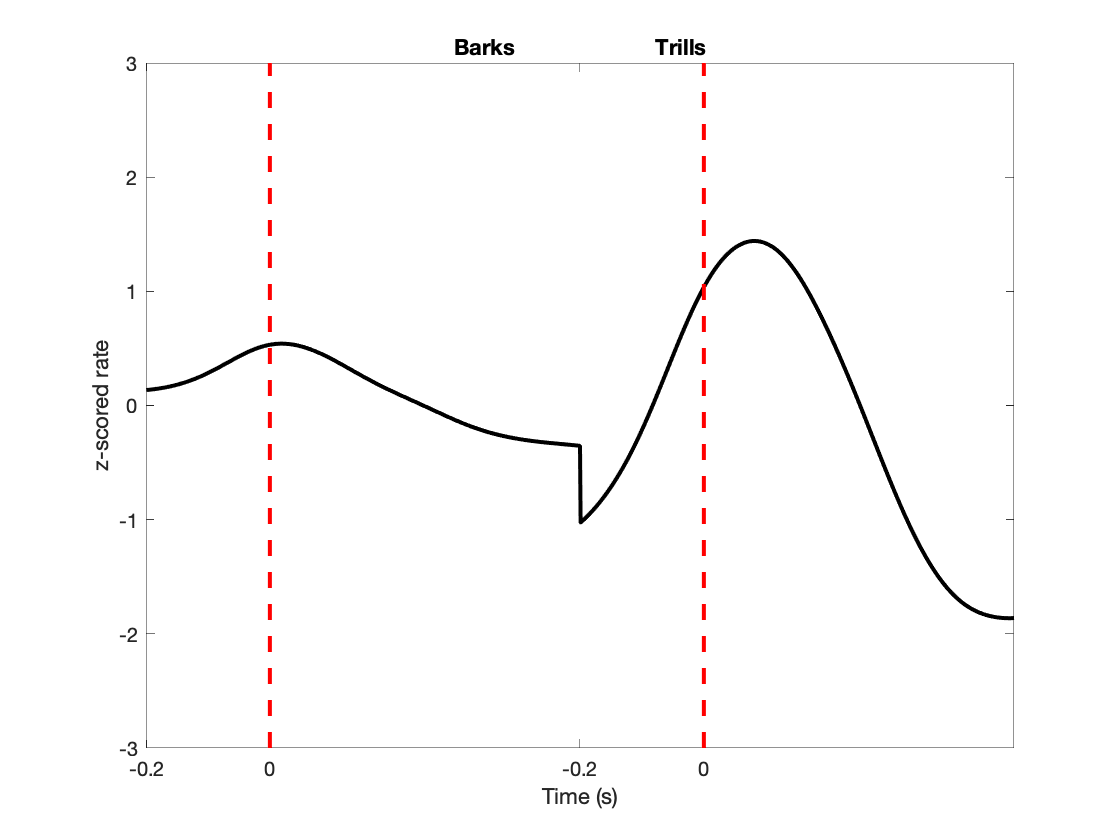


plot(mean(KDE_onset_Mat_BaTr_ZS(T==Clust,:)), 'k-', 'LineWidth',2)
xlim([0 size(KDE_onset_Mat_BaTr_ZS,2)])
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
hold on
% Barks onset
line([-Tstart -Tstart], CLim,'Color','r','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), CLim,'Color','r','LineStyle','--', 'LineWidth',2)
ylabel('z-scored rate')
title('Barks                       Trills')
hold off


% cluster 3 good example 0620_SSS_3_131
Clust=3;
IndSSU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSSU));
IndSMU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSMU));
fprintf(1,'**** Cluster %d *****\n%d units, %d single units, %d multi-units\n', Clust, sum(T==Clust),length(IndSSU),length(IndSMU))

**** Cluster 3 *****
36 units, 21 single units, 15 multi-units


for ii=1:length(IndSSU)
    fprintf('Single Unit: %s\n',ListSSU(IndSSU(ii)).name)
end

Single Unit: 59834_20190611_SSS_1-183.mat
Single Unit: 59834_20190616_SSS_2-125.mat
Single Unit: 59834_20190618_SSS_1-77.mat
Single Unit: 59834_20190618_SSS_2-145.mat
Single Unit: 59834_20190619_SSS_1-78.mat
Single Unit: 59834_20190620_SSS_1-81.mat
Single Unit: 59834_20190621_SSS_1-76.mat
Single Unit: 59834_20190621_SSS_2-112.mat
Single Unit: 59834_20190622_SSS_1-84.mat
Single Unit: 59834_20190623_SSS_1-80.mat
Single Unit: 59834_20190626_SSS_1-87.mat
Single Unit: 59834_20190627_SSM_3-322.mat
Single Unit: 59834_20190627_SSS_1-72.mat
Single Unit: 59834_20190628_SSS_1-98.mat
Single Unit: 59834_20190629_SSS_1-79.mat
Single Unit: 59834_20190630_SSS_1-72.mat
Single Unit: 59834_20190702_SSS_4-233.mat
Single Unit: 59834_20190704_SSS_1-74.mat
Single Unit: 59834_20190705_SSS_2-261.mat
Single Unit: 59834_20190706_SSS_2-188.mat
Single Unit: 59834_20190707_SSS_2-195.mat


for ii=1:length(IndSMU)
    fprintf('Multi Unit: %s\n',ListSSU(IndSMU(ii)).name)
end

Multi Unit: 59834_20190607_SSM_2-183.mat
Multi Unit: 59834_20190612_SSM_1-75.mat
Multi Unit: 59834_20190616_SSS_3-149.mat
Multi Unit: 59834_20190617_SSM_1-78.mat
Multi Unit: 59834_20190627_SSS_4-316.mat
Multi Unit: 59834_20190628_SSS_4-228.mat
Multi Unit: 59834_20190629_SSM_2-278.mat
Multi Unit: 59834_20190629_SSS_4-259.mat
Multi Unit: 59834_20190630_SSS_4-216.mat
Multi Unit: 59834_20190704_SSS_4-198.mat
Multi Unit: 59834_20190705_SSM_1-70.mat
Multi Unit: 59834_20190705_SSM_3-195.mat
Multi Unit: 59834_20190705_SSS_4-262.mat
Multi Unit: 59834_20190706_SSM_1-300.mat
Multi Unit: 59834_20190706_SSM_4-250.mat


fprintf(1,' Plot ZS data Cluster %d \n', Clust)

 Plot ZS data Cluster 3 


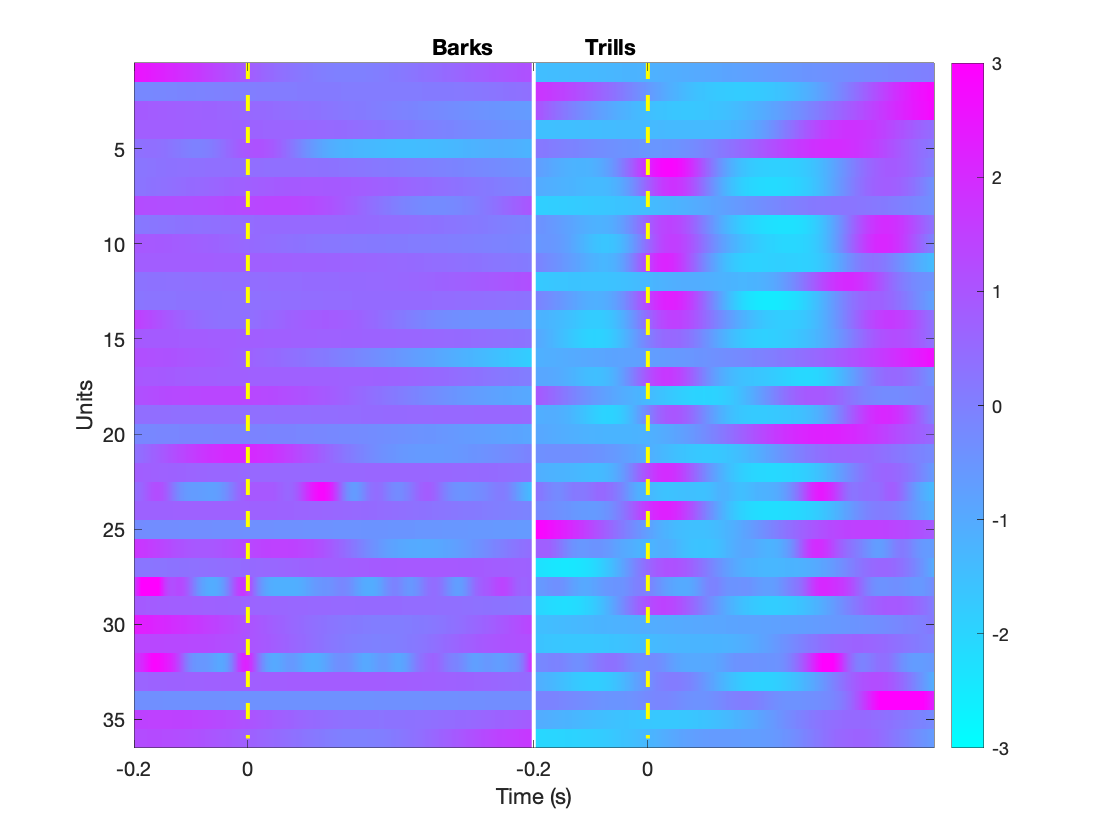

imagesc(KDE_onset_Mat_BaTr_ZS(T==Clust,:))
if CLim01
    caxis(CLim)
else
    CLim = caxis;
end
colorbar()
colormap('cool')
hold on
% delimiting Barks from Trills
line(TBa*ones(2,1), [-1 sum(T==Clust)+1],'Color', 'w', 'LineWidth',2)
hold on
% Barks onset
line([-Tstart -Tstart], [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
ylabel('Units')
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
title('Barks               Trills')
hold off

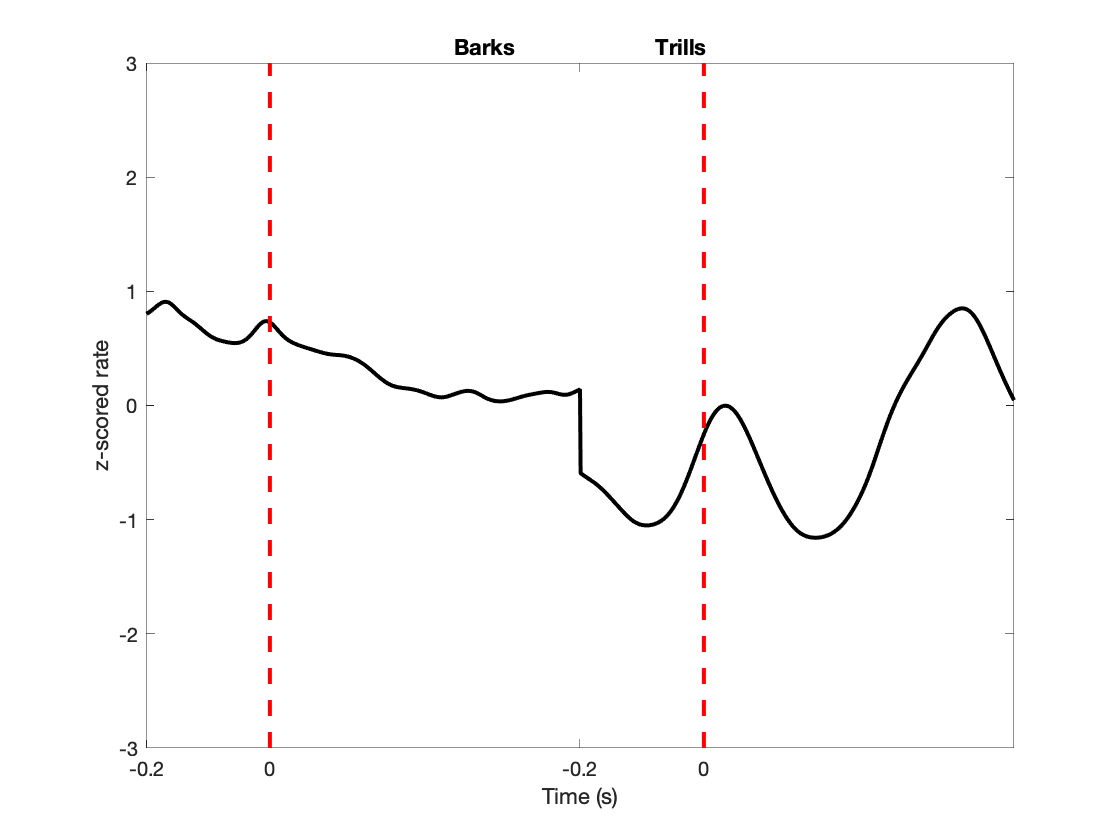


plot(mean(KDE_onset_Mat_BaTr_ZS(T==Clust,:)), 'k-', 'LineWidth',2)
xlim([0 size(KDE_onset_Mat_BaTr_ZS,2)])
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
hold on
% Barks onset
line([-Tstart -Tstart], CLim,'Color','r','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), CLim,'Color','r','LineStyle','--', 'LineWidth',2)
ylabel('z-scored rate')
title('Barks                       Trills')
hold off


% cluster 4
Clust=4;
IndSSU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSSU));
IndSMU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSMU));
fprintf(1,'**** Cluster %d *****\n%d units, %d single units, %d multi-units\n', Clust, sum(T==Clust),length(IndSSU),length(IndSMU))

**** Cluster 4 *****
179 units, 45 single units, 134 multi-units


for ii=1:length(IndSSU)
    fprintf('Single Unit: %s\n',ListSSU(IndSSU(ii)).name)
end

Single Unit: 59834_20190611_SSS_3-181.mat
Single Unit: 59834_20190612_SSS_2-93.mat
Single Unit: 59834_20190612_SSS_3-191.mat
Single Unit: 59834_20190612_SSS_3-193.mat
Single Unit: 59834_20190612_SSS_3-22.mat
Single Unit: 59834_20190613_SSS_3-127.mat
Single Unit: 59834_20190613_SSS_3-141.mat
Single Unit: 59834_20190614_SSS_1-193.mat
Single Unit: 59834_20190614_SSS_3-190.mat
Single Unit: 59834_20190616_SSS_1-77.mat
Single Unit: 59834_20190616_SSS_3-137.mat
Single Unit: 59834_20190616_SSS_3-203.mat
Single Unit: 59834_20190617_SSS_3-155.mat
Single Unit: 59834_20190618_SSS_3-168.mat
Single Unit: 59834_20190619_SSS_3-154.mat
Single Unit: 59834_20190619_SSS_3-168.mat
Single Unit: 59834_20190619_SSS_4-222.mat
Single Unit: 59834_20190620_SSS_3-131.mat
Single Unit: 59834_20190621_SSS_3-168.mat
Single Unit: 59834_20190622_SSS_3-152.mat
Single Unit: 59834_20190623_SSS_3-222.mat
Single Unit: 59834_20190623_SSS_3-223.mat
Single Unit: 59834_20190626_SSS_3-173.mat
Single Unit: 59834_20190627_SSS_3-323

for ii=1:length(IndSMU)
    fprintf('Multi Unit: %s\n',ListSSU(IndSMU(ii)).name)
end

Multi Unit: 59834_20190607_SSM_1-203.mat
Multi Unit: 59834_20190607_SSM_2-175.mat
Multi Unit: 59834_20190607_SSM_2-201.mat
Multi Unit: 59834_20190611_SSM_3-186.mat
Multi Unit: 59834_20190611_SSS_1-109.mat
Multi Unit: 59834_20190612_SSM_2-101.mat
Multi Unit: 59834_20190612_SSS_3-157.mat
Multi Unit: 59834_20190612_SSS_3-165.mat
Multi Unit: 59834_20190612_SSS_3-169.mat
Multi Unit: 59834_20190613_SSM_2-117.mat
Multi Unit: 59834_20190613_SSM_2-89.mat
Multi Unit: 59834_20190613_SSM_3-123.mat
Multi Unit: 59834_20190613_SSM_3-147.mat
Multi Unit: 59834_20190613_SSS_3-137.mat
Multi Unit: 59834_20190614_SSM_1-92.mat
Multi Unit: 59834_20190614_SSM_2-126.mat
Multi Unit: 59834_20190614_SSM_2-140.mat
Multi Unit: 59834_20190614_SSM_3-162.mat
Multi Unit: 59834_20190614_SSM_3-219.mat
Multi Unit: 59834_20190616_SSM_2-212.mat
Multi Unit: 59834_20190616_SSM_3-175.mat
Multi Unit: 59834_20190616_SSM_3-201.mat
Multi Unit: 59834_20190616_SSS_1-73.mat
Multi Unit: 59834_20190618_SSM_2-121.mat
Multi Unit: 59834_2

fprintf(1,' Plot ZS data Cluster %d \n', Clust)

 Plot ZS data Cluster 4 


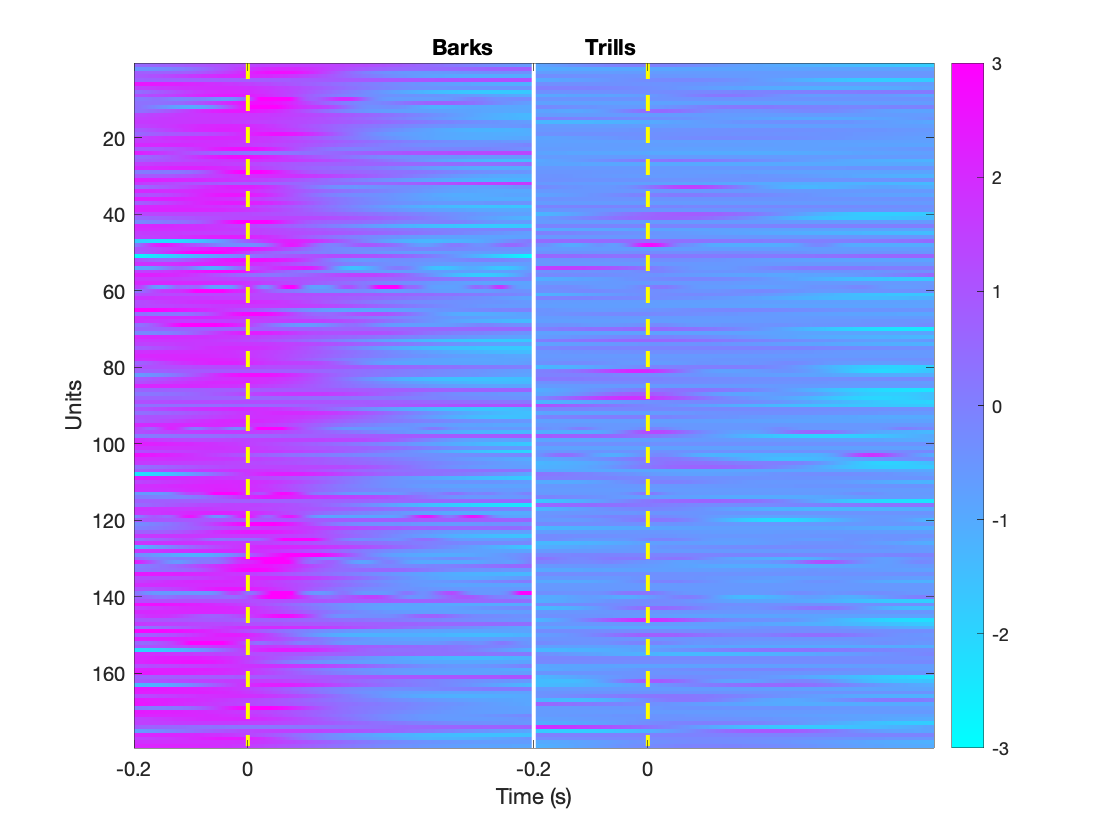

imagesc(KDE_onset_Mat_BaTr_ZS(T==Clust,:))
if CLim01
    caxis(CLim)
else
    CLim = caxis;
end
colorbar()
colormap('cool')
hold on
% delimiting Barks from Trills
line(TBa*ones(2,1), [-1 sum(T==Clust)+1],'Color', 'w', 'LineWidth',2)
hold on
% Barks onset
line([-Tstart -Tstart], [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
ylabel('Units')
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
title('Barks               Trills')
hold off

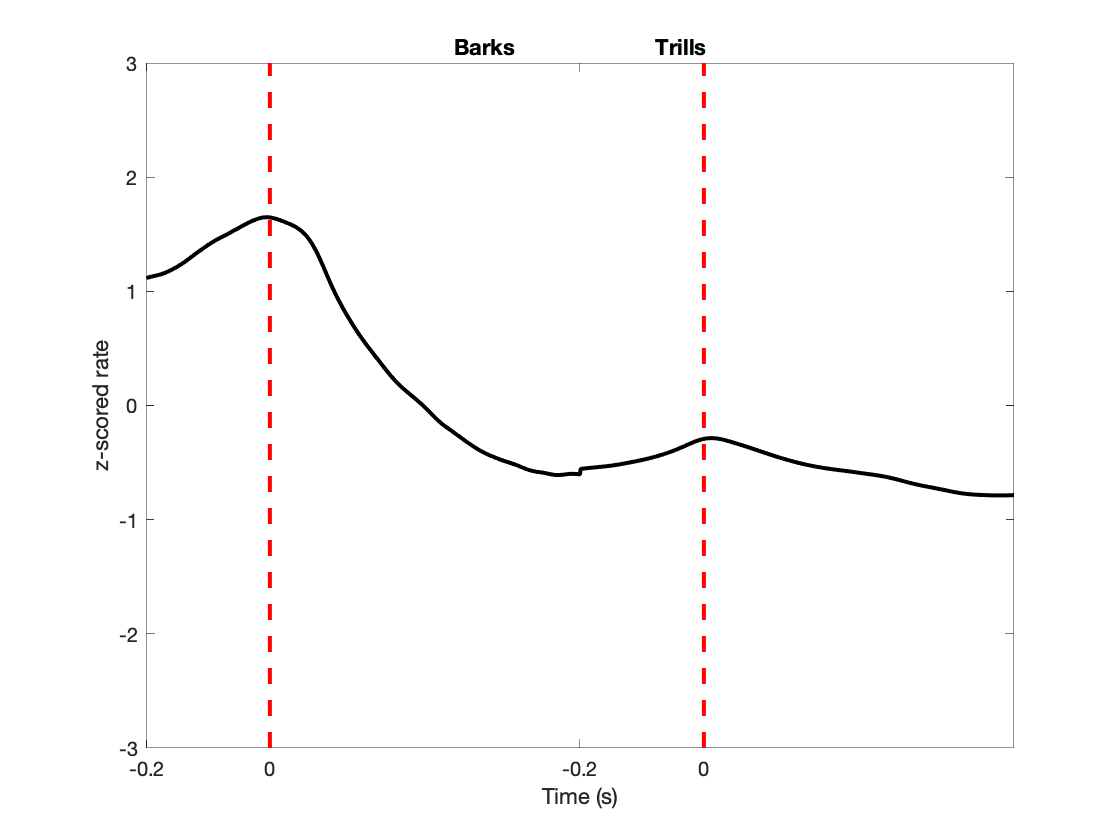


plot(mean(KDE_onset_Mat_BaTr_ZS(T==Clust,:)), 'k-', 'LineWidth',2)
xlim([0 size(KDE_onset_Mat_BaTr_ZS,2)])
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
hold on
% Barks onset
line([-Tstart -Tstart], CLim,'Color','r','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), CLim,'Color','r','LineStyle','--', 'LineWidth',2)
ylabel('z-scored rate')
title('Barks                       Trills')
hold off


% cluster 5
Clust=5;
IndSSU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSSU));
IndSMU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSMU));
fprintf(1,'**** Cluster %d *****\n%d units, %d single units, %d multi-units\n', Clust, sum(T==Clust),length(IndSSU),length(IndSMU))

**** Cluster 5 *****
33 units, 15 single units, 18 multi-units


for ii=1:length(IndSSU)
    fprintf('Single Unit: %s\n',ListSSU(IndSSU(ii)).name)
end

Single Unit: 59834_20190612_SSM_2-196.mat
Single Unit: 59834_20190612_SSS_2-109.mat
Single Unit: 59834_20190613_SSS_2-105.mat
Single Unit: 59834_20190614_SSS_2-132.mat
Single Unit: 59834_20190616_SSS_2-83.mat
Single Unit: 59834_20190617_SSS_2-94.mat
Single Unit: 59834_20190618_SSS_2-99.mat
Single Unit: 59834_20190619_SSS_2-108.mat
Single Unit: 59834_20190620_SSS_2-107.mat
Single Unit: 59834_20190630_SSS_2-128.mat
Single Unit: 59834_20190705_SSS_2-114.mat
Single Unit: 59834_20190706_SSS_2-144.mat
Single Unit: 59834_20190707_SSS_2-165.mat
Single Unit: 59834_20190710_SSS_2-114.mat
Single Unit: 59834_20190711_SSS_2-160.mat


for ii=1:length(IndSMU)
    fprintf('Multi Unit: %s\n',ListSSU(IndSMU(ii)).name)
end

Multi Unit: 59834_20190613_SSM_2-103.mat
Multi Unit: 59834_20190619_SSM_2-134.mat
Multi Unit: 59834_20190621_SSM_2-102.mat
Multi Unit: 59834_20190621_SSM_2-163.mat
Multi Unit: 59834_20190622_SSM_2-200.mat
Multi Unit: 59834_20190623_SSS_1-88.mat
Multi Unit: 59834_20190623_SSS_2-116.mat
Multi Unit: 59834_20190626_SSM_2-169.mat
Multi Unit: 59834_20190626_SSM_2-226.mat
Multi Unit: 59834_20190626_SSS_1-109.mat
Multi Unit: 59834_20190627_SSM_2-202.mat
Multi Unit: 59834_20190701_SSM_2-211.mat
Multi Unit: 59834_20190702_SSM_2-141.mat
Multi Unit: 59834_20190702_SSM_2-245.mat
Multi Unit: 59834_20190704_SSM_2-124.mat
Multi Unit: 59834_20190706_SSM_2-152.mat
Multi Unit: 59834_20190707_SSS_2-259.mat
Multi Unit: 59834_20190710_SSM_1-68.mat


fprintf(1,' Plot ZS data Cluster %d \n', Clust)

 Plot ZS data Cluster 5 


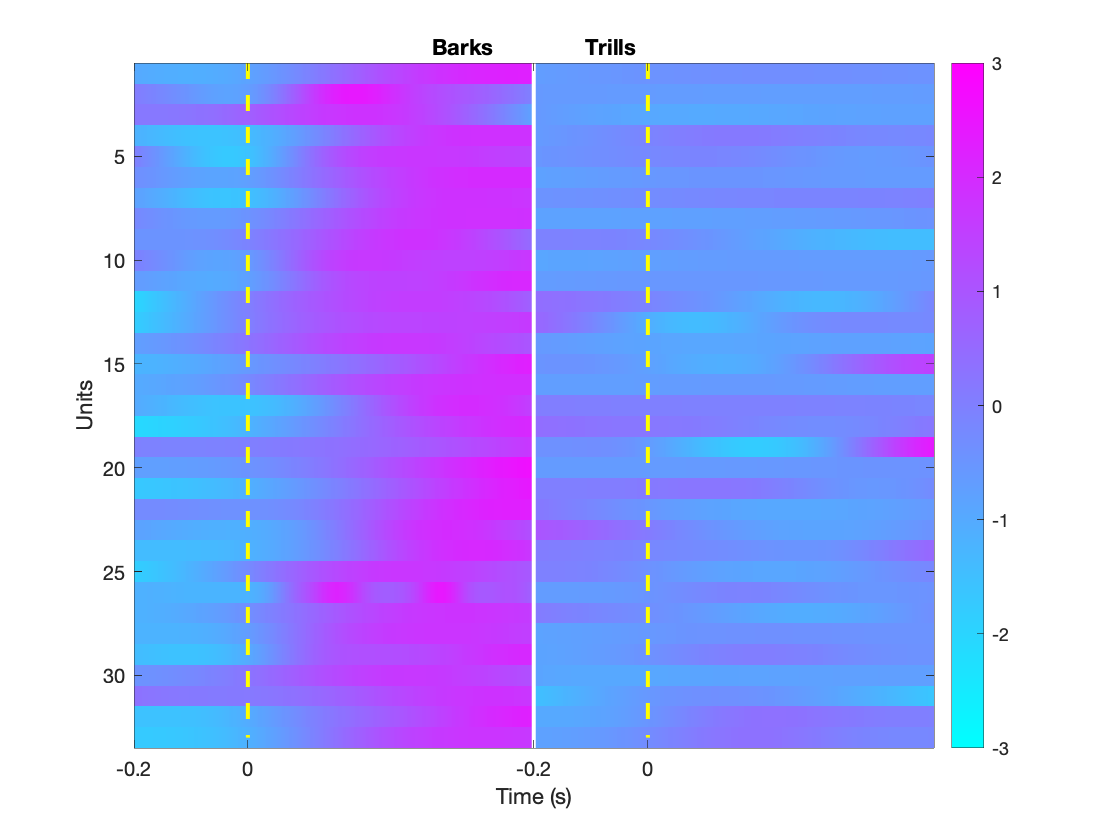

imagesc(KDE_onset_Mat_BaTr_ZS(T==Clust,:))
if CLim01
    caxis(CLim)
else
    CLim = caxis;
end
colorbar()
colormap('cool')
hold on
% delimiting Barks from Trills
line(TBa*ones(2,1), [-1 sum(T==Clust)+1],'Color', 'w', 'LineWidth',2)
hold on
% Barks onset
line([-Tstart -Tstart], [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
ylabel('Units')
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
title('Barks               Trills')
hold off

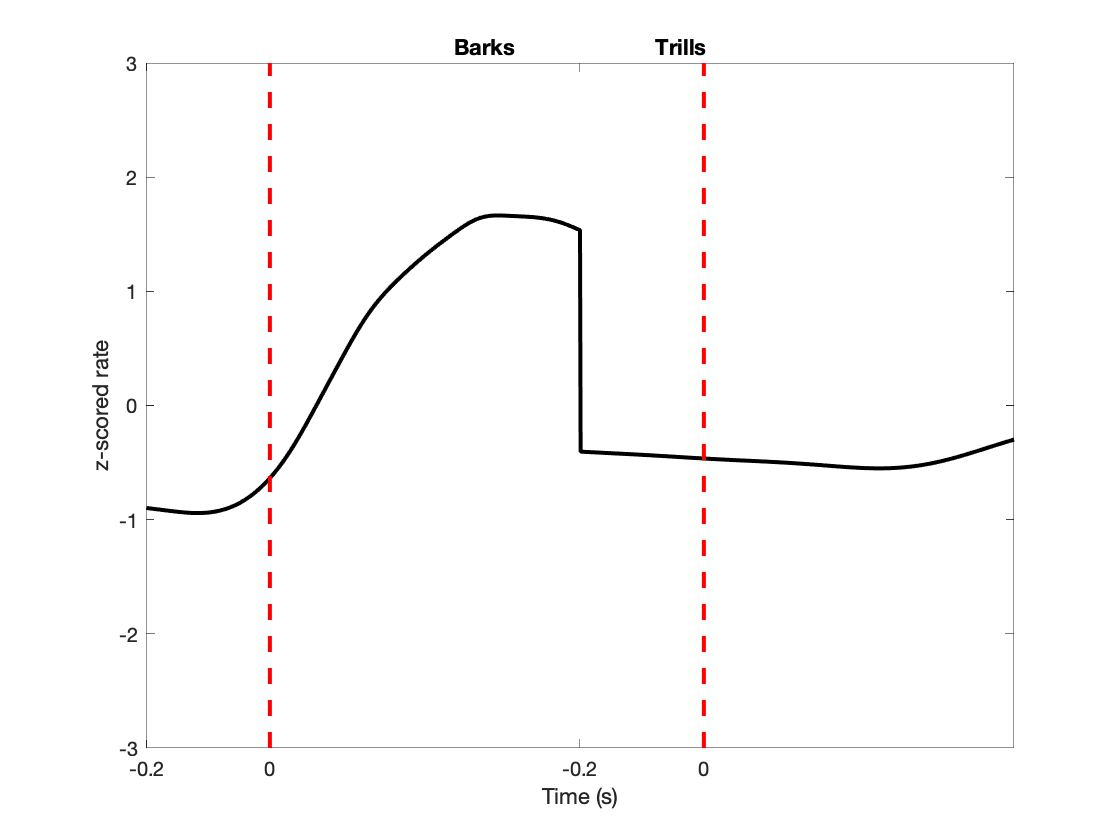


plot(mean(KDE_onset_Mat_BaTr_ZS(T==Clust,:)), 'k-', 'LineWidth',2)
xlim([0 size(KDE_onset_Mat_BaTr_ZS,2)])
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
hold on
% Barks onset
line([-Tstart -Tstart], CLim,'Color','r','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), CLim,'Color','r','LineStyle','--', 'LineWidth',2)
ylabel('z-scored rate')
title('Barks                       Trills')
hold off



% cluster 6
Clust=6;
IndSSU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSSU));
IndSMU = intersect(GoodCellIndices(BaTr_ind(T==Clust)), find(SSMU));
fprintf(1,'**** Cluster %d *****\n%d units, %d single units, %d multi-units\n', Clust, sum(T==Clust),length(IndSSU),length(IndSMU))

**** Cluster 6 *****
42 units, 20 single units, 22 multi-units


for ii=1:length(IndSSU)
    fprintf('Single Unit: %s\n',ListSSU(IndSSU(ii)).name)
end

Single Unit: 59834_20190616_SSS_3-202.mat
Single Unit: 59834_20190618_SSS_3-176.mat
Single Unit: 59834_20190619_SSS_2-148.mat
Single Unit: 59834_20190620_SSS_2-123.mat
Single Unit: 59834_20190620_SSS_2-215.mat
Single Unit: 59834_20190621_SSS_2-124.mat
Single Unit: 59834_20190627_SSS_2-176.mat
Single Unit: 59834_20190628_SSS_2-118.mat
Single Unit: 59834_20190629_SSS_2-129.mat
Single Unit: 59834_20190629_SSS_3-213.mat
Single Unit: 59834_20190630_SSM_2-223.mat
Single Unit: 59834_20190630_SSS_2-150.mat
Single Unit: 59834_20190701_SSS_2-167.mat
Single Unit: 59834_20190702_SSS_2-85.mat
Single Unit: 59834_20190702_SSS_3-187.mat
Single Unit: 59834_20190704_SSS_2-130.mat
Single Unit: 59834_20190704_SSS_2-134.mat
Single Unit: 59834_20190704_SSS_3-168.mat
Single Unit: 59834_20190705_SSM_2-126.mat
Single Unit: 59834_20190706_SSS_2-172.mat


for ii=1:length(IndSMU)
    fprintf('Multi Unit: %s\n',ListSSU(IndSMU(ii)).name)
end

Multi Unit: 59834_20190611_SSM_1-87.mat
Multi Unit: 59834_20190612_SSM_2-119.mat
Multi Unit: 59834_20190614_SSM_1-203.mat
Multi Unit: 59834_20190616_SSS_2-131.mat
Multi Unit: 59834_20190617_SSM_2-132.mat
Multi Unit: 59834_20190617_SSM_2-188.mat
Multi Unit: 59834_20190618_SSM_1-73.mat
Multi Unit: 59834_20190620_SSM_2-127.mat
Multi Unit: 59834_20190622_SSS_2-148.mat
Multi Unit: 59834_20190623_SSM_2-118.mat
Multi Unit: 59834_20190623_SSS_2-128.mat
Multi Unit: 59834_20190627_SSM_2-168.mat
Multi Unit: 59834_20190627_SSM_2-190.mat
Multi Unit: 59834_20190627_SSM_2-326.mat
Multi Unit: 59834_20190628_SSM_2-238.mat
Multi Unit: 59834_20190629_SSM_2-143.mat
Multi Unit: 59834_20190629_SSM_2-161.mat
Multi Unit: 59834_20190701_SSM_2-175.mat
Multi Unit: 59834_20190701_SSM_2-197.mat
Multi Unit: 59834_20190701_SSM_2-217.mat
Multi Unit: 59834_20190705_SSS_4-243.mat
Multi Unit: 59834_20190707_SSM_2-171.mat


fprintf(1,' Plot ZS data Cluster %d \n', Clust)

 Plot ZS data Cluster 6 


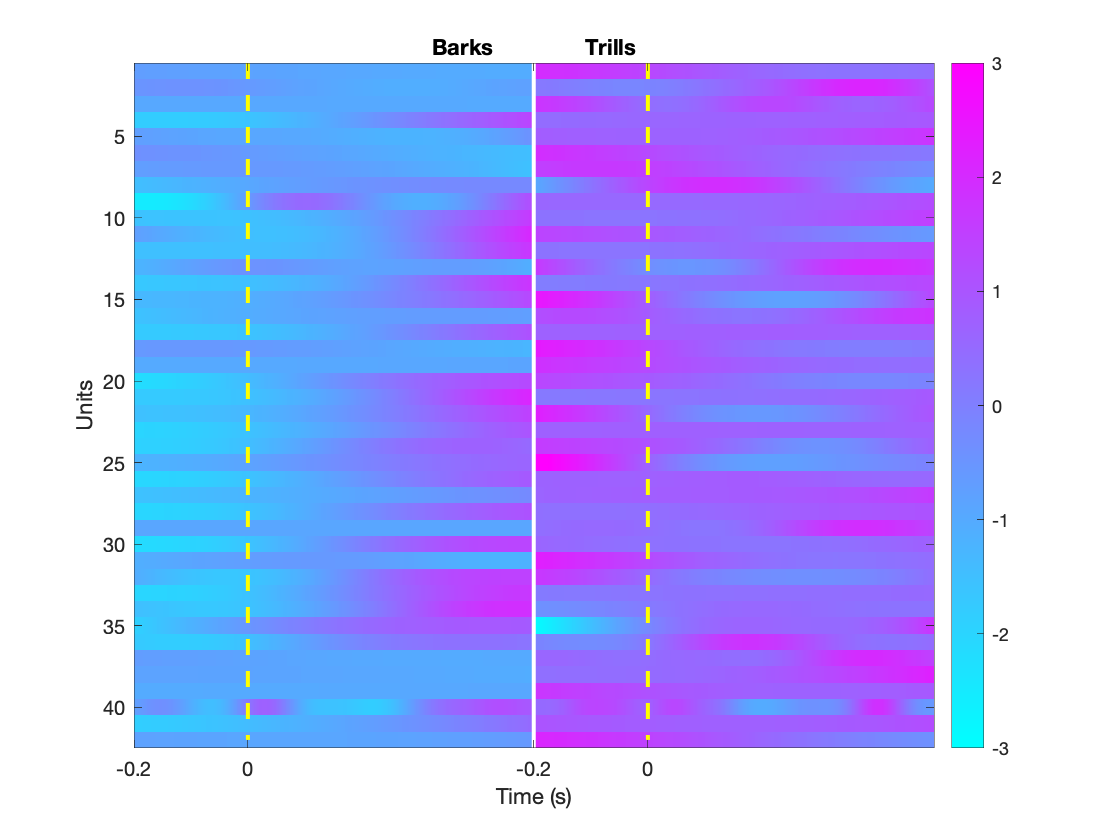

imagesc(KDE_onset_Mat_BaTr_ZS(T==Clust,:))
if CLim01
    caxis(CLim)
else
    CLim = caxis;
end
colorbar()
colormap('cool')
hold on
% delimiting Barks from Trills
line(TBa*ones(2,1), [-1 sum(T==Clust)+1],'Color', 'w', 'LineWidth',2)
hold on
% Barks onset
line([-Tstart -Tstart], [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), [0 sum(T==Clust)],'Color','y','LineStyle','--', 'LineWidth',2)
ylabel('Units')
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
title('Barks               Trills')
hold off

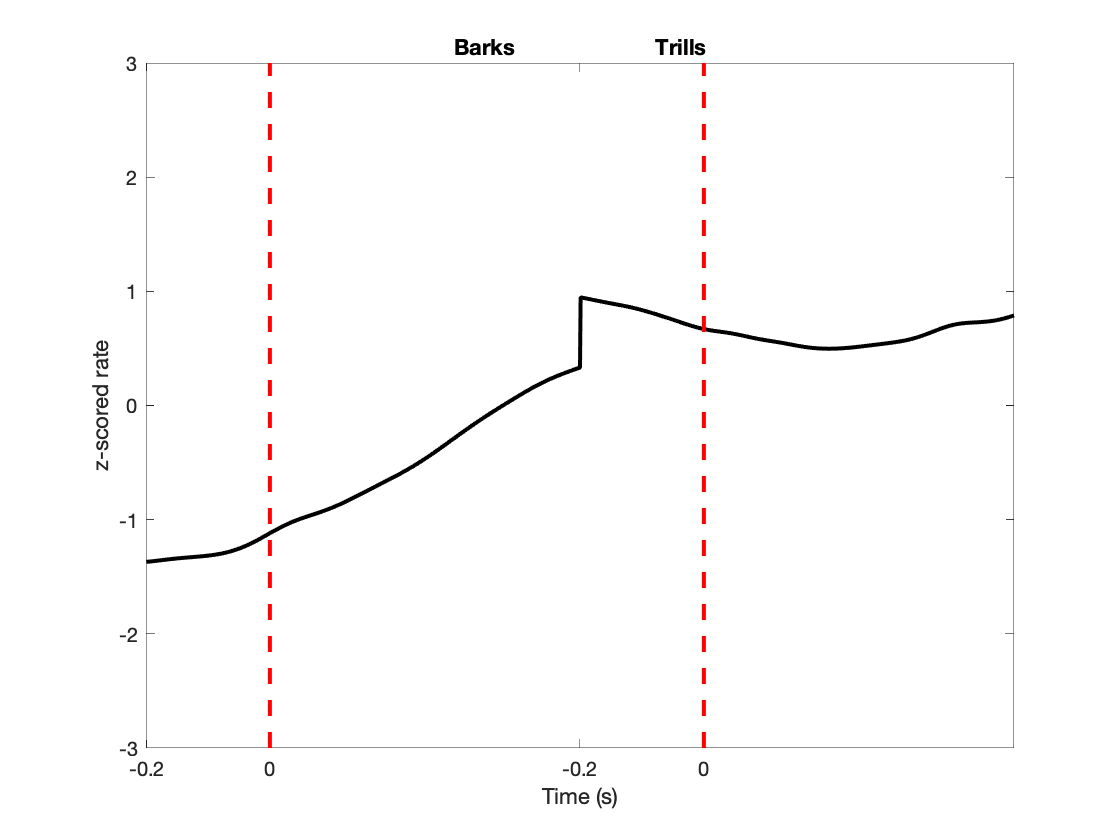


plot(mean(KDE_onset_Mat_BaTr_ZS(T==Clust,:)), 'k-', 'LineWidth',2)
xlim([0 size(KDE_onset_Mat_BaTr_ZS,2)])
xlabel('Time (s)')
xticks([1 -Tstart TBa TBa-Tstart])
xticklabels([Tstart/10^3 0 Tstart/10^3 0])
hold on
% Barks onset
line([-Tstart -Tstart], CLim,'Color','r','LineStyle','--', 'LineWidth',2)
hold on
% Trills onset
line((-Tstart + TBa)*ones(2,1), CLim,'Color','r','LineStyle','--', 'LineWidth',2)
ylabel('z-scored rate')
title('Barks                       Trills')
hold off

save('explore_populationSU_data.mat')

% For each day, each logger, each unit find the average spike rate
PLOT=1;
MeanSR4Calulations = 1; % Values in Hz of the mean SR for doing calculations
NDays = length(Dates);
HypNSU = 200;
TimeStep = 10*60; % Time resolution in seconds at which the spike rate shoule be calculated
MaxRecTime = 60*60*6;
TimePoints = 0:TimeStep:MaxRecTime;
SpikeRate = nan(HypNSU,length(TimePoints)-1);% will contain spike rate in Hz
KDE = nan(HypNSU,length(TimePoints)-1);% will contain spike rate in Hz
KDE_error = cell(HypNSU,1);% will contain spike rate error in Hz
Peak2Peak = nan(HypNSU,length(TimePoints)-1);% will contain mean spike amplitude along time
SpikeLife = nan(HypNSU,1); % Duration in minutes of period containing a spike from the cell
SD_SR = nan(HypNSU,1);
Mean_SR = nan(HypNSU,1); % average mean SR in Hz of each cell only counting time windows of 10min where there is at least one spike (cell still active)
Bat_ID = nan(HypNSU,1);
Date_ID = nan(HypNSU,1);
Tetrode_ID = nan(HypNSU,1);
SS_ID = cell(HypNSU,1);
Mean_Peak2Peak = nan(HypNSU,1);
SpikeShape = cell(HypNSU,4);
Alpha = 0.01; % Detection thershold for significant spike rate modulation before correction for false positive
SignWinVoc = nan(HypNSU,1); % number of time bin in the KDE when producing the vocalizations above the mean baseline firing rate by twice the SD of the baseline firing rate
SignWinHear = nan(HypNSU,1);% number of time bin in the KDE when hearing the vocalizations above the mean baseline firing rate by twice the SD of the baseline firing rate
ProdCellGood = nan(HypNSU,1);

CellCount=0;
for dd=1:NDays
    Date = Dates(dd);
    fprintf(1,'%d\n',Date)
    Path2Data = fullfile(Path2AllData, ['20' num2str(Date)]);
    % Get the number of loggers
    Logger_dirs = dir(fullfile(Path2Data, '*ogger*'));
    Logger_dirs=Logger_dirs([Logger_dirs.isdir]);
    NLogger = length(Logger_dirs);
    % Identify the type of logger and extract neural data
    LoggerType = cell(NLogger,1);
    % LOAD the data of KDE to do a test for vocalization production
    FileData = dir(fullfile(Path2Data, sprintf('%d_*_VocExtractData_*', Date)));
    load(fullfile(FileData(1).folder,FileData(1).name), 'SpikeTimesVoc')
    Ind_ = strfind(FileData(1).name, '_');
    Delay = str2double(FileData(1).name(Ind_(end) + (1:3)));
    for ll=1:NLogger
        fprintf(1,'%s\n',Logger_dirs(ll).name)
        LData_folder = fullfile(Logger_dirs(ll).folder, Logger_dirs(ll).name,'extracted_data');
        LDir = dir(fullfile(LData_folder, '*CSC*.mat'));
        LData = load(fullfile(LDir(1).folder, LDir(1).name), 'logger_type', 'logger_serial_number');
        LoggerType{ll}  = LData.logger_type;
        if strcmp(LoggerType{ll}, 'Mous') || strcmp(LoggerType{ll}, 'Rat')
            SU_files = dir(fullfile(LData_folder, '*TT*SS*.mat'));
            NSU = length(SU_files);
            %Get the Bat-ID for that logger
            RowData = find((cell2mat(RecTableData(2:end,1))== Date)) +1;
            DataInfo = RecTableData(RowData,:);
            NL_ID = cell2mat(DataInfo(NLCol));
            NLCol_local = NLCol(NL_ID==str2double(LData.logger_serial_number));
            Bat_ID_local = DataInfo{BatIDCol(find(BatIDCol<NLCol_local,1,'last'))};
            if Bat_ID_local==11689 % Only run on Hodor

                for uu=1:NSU
                    CellCount = CellCount+1;
                    fprintf(1,'Cell %d\n',CellCount)
                    Cell = load(fullfile(SU_files(uu).folder, SU_files(uu).name)); % This load the Spike_arrival_times in micro seconds and the Spike_snippets in microVolts, ceiled at 500uV for spike sorting projection
                    SpikeTimes = (Cell.Spike_arrival_times-Cell.Spike_arrival_times(1))*10^-6; % Spike arrival times centered to the first spike, in seconds

                    % Find the best channel to calculate the peak2peak value
                    % (channel with largest spike trace)
                    P2P_all = nan(size(Cell.Spike_snippets,3),4);
                    for cc=1:4 % calculate for each channel the peak2peak for all spikes
                        P2P_all(:,cc)=reshape(max(Cell.Spike_snippets(:,cc,:),[],1) - min(Cell.Spike_snippets(:,cc,:),[],1),size(Cell.Spike_snippets,3),1);
                    end
                    [~,I]=max(P2P_all,[],2);
                    Best_c = nan(1,4);
                    for cc=1:4
                        Best_c(cc) = sum(I==cc);
                    end
                    [~,Best_c] = max(Best_c); % This is the channel with the largest spike


                    for tt=1:(length(TimePoints)-1)
                        Spike_local = (SpikeTimes>=TimePoints(tt)) .* (SpikeTimes<=TimePoints(tt+1));
                        SpikeRate(CellCount,tt) = sum(Spike_local)/TimeStep; % this is the local spike rate in Hertz
                        SpikeInd = find(Spike_local);
                        % calculate for each channel the average peak2peak for the spikes occuring during that time slot
                        Peak2Peak(CellCount,tt) = ADBitVolts_sorting.*mean(max(Cell.Spike_snippets(:,Best_c,SpikeInd),[],1) - min(Cell.Spike_snippets(:,Best_c,SpikeInd),[],1));
                    end



                    % calculate average statistics for that cell
                    SpikeLife(CellCount) = (TimePoints(find(~isnan(Peak2Peak(CellCount,:)),1,'Last'))- TimePoints(find(~isnan(Peak2Peak(CellCount,:)),1,'First')))/60;
                    [KDE(CellCount,:),~,KDE_error{CellCount}] = kde_wrapper(SpikeTimes,TimePoints(2:end)-TimeStep/2,1/TimeStep);
                    Mean_Peak2Peak(CellCount) = mean(P2P_all(:,Best_c));
                    Mean_SR(CellCount) = mean(SpikeRate(CellCount,find(~isnan(Peak2Peak(CellCount,:)))));
                    SD_SR(CellCount) = std(SpikeRate(CellCount,find(~isnan(Peak2Peak(CellCount,:)))));
                    Bat_ID(CellCount) = Bat_ID_local;
                    Date_ID(CellCount) = str2double(['20' num2str(Date)]);
                    TTInd = strfind(SU_files(uu).name, 'TT');
                    Tetrode_ID(CellCount) = str2double(SU_files(uu).name(TTInd+2));
                    SSInd = strfind(SU_files(uu).name, 'SS');
                    SS_ID{CellCount} = SU_files(uu).name(SSInd+(3:4));

                    % extract the average spike shape for that cell
                    for cc=1:4
                        SpikeShape{CellCount,cc}=nan(2,size(Cell.Spike_snippets,1));
                        SpikeShape{CellCount,cc}(1,:) = mean(Cell.Spike_snippets(:,cc,:),3).*ADBitVolts_sorting;
                        SpikeShape{CellCount,cc}(2,:) = std(Cell.Spike_snippets(:,cc,:),0,3).*ADBitVolts_sorting;
                    end
                    
                    
                    % Test if the cell has a modulated spike rate compared to
                    % averaged before vocalizations (one time window with KDE
                    % away from the mean by twice SD). Rate is in spike per ms
                    % here. Test only if the average spike rate is  above 0.1Hz (1 spike every 10 seconds);
                    ST = SpikeTimesVoc.(sprintf('Logger%s',LData.logger_serial_number));
                    LogicalInd=logical((ST.Sum_Psth_KDEfiltered_VocCall{uu,1}>-Delay) .* (ST.Sum_Psth_KDEfiltered_VocCall{uu,1}<mean(ST.VocDuration+Delay)));
                    Fig0=figure(1);
                    clf(Fig0)
                    plot(ST.Sum_Psth_KDEfiltered_VocCall{uu,1}(LogicalInd), ST.Sum_Psth_KDEfiltered_VocCall{uu,2}(LogicalInd), '-k', 'LineWidth',2)
                    hold on
                    plot([min(ST.Sum_Psth_KDEfiltered_VocCall{uu,1}(LogicalInd)) max(ST.Sum_Psth_KDEfiltered_VocCall{uu,1}(LogicalInd))], MeanBaselineVoc/1000.* ones(2,1), ':r', 'LineWidth',2)
                    ylabel('Spike Rate (Hz)')
                    xlabel('Time (ms)')
                    legend('Rate','Background')
                    title(sprintf('Test for modulated spike rate M%d %d TT%d SS%s SU%d', Bat_ID(CellCount),Date_ID(CellCount), Tetrode_ID(CellCount), SS_ID{CellCount},uu))
                    
                    hold off
                    if Mean_SR(CellCount)>MeanSR4Calulations
                        if ~isempty(ST.Sum_Psth_KDEfiltered_VocBaseline) && iscell(ST.Sum_Psth_KDEfiltered_VocBaseline)
                            MeanBaselineVoc = mean(ST.Sum_Psth_KDEfiltered_VocBaseline{uu,2})*1000;% Average baseline rate in Hz
                            if MeanBaselineVoc>MeanSR4Calulations
                                Zscore = abs(ST.Sum_Psth_KDEfiltered_VocCall{uu,2}(LogicalInd) - MeanBaselineVoc/1000)/std(ST.Sum_Psth_KDEfiltered_VocBaseline{uu,2});
                                P_value = normcdf(Zscore, 'upper');
                                PV_sorted = sort(P_value);
                                
                                
                                % False Rate detection correction,
                                % Benjamini-Hochberg procedure
                                SignWinVoc(CellCount)=sum(PV_sorted<(Alpha/length(PV_sorted).*(1:length(PV_sorted))));
                            end
                        end
                        if ~isempty(ST.Sum_Psth_KDEfiltered_HearBaseline) && iscell(ST.Sum_Psth_KDEfiltered_HearBaseline)
                            MeanBaselineHear = mean(ST.Sum_Psth_KDEfiltered_HearBaseline{uu,2})*1000;% Average baseline rate in Hz
                            if MeanBaselineHear>MeanSR4Calulations
                                LogicalInd=logical((ST.Sum_Psth_KDEfiltered_HearCall{uu,1}>-Delay) .* (ST.Sum_Psth_KDEfiltered_HearCall{uu,1}<mean(ST.HearDuration(ST.HearOnlyInd)+Delay)));
                                Zscore = abs(ST.Sum_Psth_KDEfiltered_HearCall{uu,2}(LogicalInd) - MeanBaselineHear/1000)/std(ST.Sum_Psth_KDEfiltered_HearBaseline{uu,2});
                                P_value = normcdf(Zscore, 'upper');
                                PV_sorted = sort(P_value);
                                % False Rate detection correction,
                                % Benjamini-Hochberg procedure
                                SignWinHear(CellCount)=sum(PV_sorted<(Alpha/length(PV_sorted).*(1:length(PV_sorted))));
                            end
                        end

                    end

                    if PLOT
                        % Plot the average spike rate over time, the average spike
                        % amplitude over time and the mean snippets
                        Fig1=figure(2);
                        clf(Fig1)
                        yyaxis left
                        plot((TimePoints(2:end)-TimeStep/2)/60,SpikeRate(CellCount,:),'b-', 'LineWidth',2)
                        hold on
                        shadedErrorBar((TimePoints(2:end)-TimeStep/2)/60,KDE(CellCount,:),KDE_error{CellCount},{'b--', 'LineWidth',2})
                        ylabel('Spike rate (Hz)')
                        xlabel('Time (min)')
                        ylim([0 max(MeanSR4Calulations/10,Fig1.Children.YLim(2))])
                        hold on
                        if Fig1.Children.YLim(2)>MeanSR4Calulations
                            hline(MeanSR4Calulations, 'k:', 'Spike rate threshold for calculating significance')
                        end
                        yyaxis right
                        plot((TimePoints(2:end)-TimeStep/2)/60,Peak2Peak(CellCount,:),'r-', 'LineWidth',2)
                        ylabel('Spike Amplitude (uV)')
                        Fig1.Children.YLim(1)=0;
                        title(sprintf('M%d %d TT%d SS%s SU%d SignifVoc=%d SignifHear=%d', Bat_ID(CellCount),Date_ID(CellCount), Tetrode_ID(CellCount), SS_ID{CellCount},uu,SignWinVoc(CellCount),SignWinHear(CellCount)))
                        hold off
                        Fig2=figure(3);
                        clf(Fig2)
                        Fig2YLim = nan(2,4);
                        for cc=1:4
                            subplot(2,2,cc)
                            shadedErrorBar([],SpikeShape{CellCount,cc}(1,:), SpikeShape{CellCount,cc}(2,:), {'Color','k','LineWidth',2})
                            ylabel('Voltage (uVolt)')
                        end
                        for cc=1:4
                            Fig2YLim(:,cc) = Fig2.Children(cc).YLim;
                        end
                        Fig2YLim_final(1) = min(Fig2YLim(1,:));
                        Fig2YLim_final(2) = max(Fig2YLim(2,:));
                        for cc=1:4
                            Fig2.Children(cc).YLim = Fig2YLim_final;
                        end
                        sgtitle(sprintf('Spike shape M%d %d TT%d SS%s SU%d', Bat_ID(CellCount),Date_ID(CellCount), Tetrode_ID(CellCount), SS_ID{CellCount},uu))
                        print(Fig1,fullfile(Path2Data,sprintf('%d_Logger%s_TT%d_SS%s_SU%d_Rate.pdf', Date, LData.logger_serial_number,Tetrode_ID(CellCount),SS_ID{CellCount},uu)),'-dpdf')
                        print(Fig2,fullfile(Path2Data,sprintf('%d_Logger%s_TT%d_SS%s_SU%d_Snippets.pdf', Date, LData.logger_serial_number,Tetrode_ID(CellCount),SS_ID{CellCount},uu)),'-dpdf')
    %                     if SignWinVoc(CellCount)>0 || SignWinHear(CellCount)>0
        %                     pause()
        %                 end
                        pause(5)
                    end
                    if SignWinVoc(CellCount)>ThreshSig
                        ProdCellGood(CellCount)=input('Good Production Cell?');
                    end
                end
            end
            
        end
    end
end


% Plot the histogram of cells Mean_SR
figure()
[~,edges] = histcounts(log10(Mean_SR));
histogram(Mean_SR,10.^edges)
set(gca, 'XScale','log')
ylabel('# Cells')
xlabel('Average rate (Hz)')

% Scatter plot of mean_SR and Mean amplitude of the spikes

figure()
subplot(2,2,1)
plot(Mean_SR, Mean_Peak2Peak, 'k.','MarkerSize',10)
hold on
plot(Mean_SR(SignWinVoc>ThreshSig), Mean_Peak2Peak(SignWinVoc>ThreshSig), 'r.','MarkerSize',10)
set(gca, 'XScale','log')
ylabel('Spike Amplitude uV')
xlabel('Average rate (Hz)')
hold off

subplot(2,2,2)
plot(Mean_SR, Mean_Peak2Peak, 'k.','MarkerSize',10)
hold on
plot(Mean_SR(SignWinHear>ThreshSig), Mean_Peak2Peak(SignWinHear>ThreshSig), 'c.','MarkerSize',10)
set(gca, 'XScale','log')
ylabel('Spike Amplitude uV')
xlabel('Average rate (Hz)')
hold off

% Scatter plot of mean_SR and Recording duration
subplot(2,2,3)
plot(Mean_SR, SpikeLife, 'k.','MarkerSize',10)
hold on
plot(Mean_SR(SignWinVoc>ThreshSig), SpikeLife(SignWinVoc>ThreshSig), 'r.','MarkerSize',10)
set(gca, 'XScale','log')
ylabel('Recording duration (min)')
ylim([0 400])
xlabel('Average rate (Hz)')
hold off

subplot(2,2,4)
plot(Mean_SR, SpikeLife, 'k.','MarkerSize',10)
hold on
plot(Mean_SR(SignWinHear>ThreshSig), SpikeLife(SignWinHear>ThreshSig), 'c.','MarkerSize',10)
set(gca, 'XScale','log')
ylim([0 400])
ylabel('Recording duration (min)')
xlabel('Average rate (Hz)')
hold off
save('/Volumes/server_home/users/JulieE/LMC_HoHa/PopulationAnalysis.mat')

## Look at cell one by one

load('/Volumes/server_home/users/JulieE/LMC_HoHa/PopulationAnalysis.mat')
% First voc prod modulated
% ProdCell = find(SignWinVoc>ThreshSig);
% for cc=1:length(ProdCell)
%     fprintf(1,'Date: %d\n',Date_ID(ProdCell(cc)))
%     fprintf(1,'Bat: %d\n',Bat_ID(ProdCell(cc)))
%     fprintf(1,'T%d\n',Tetrode_ID(ProdCell(cc)));
%     fprintf(1,'SS%s\n',SS_ID{ProdCell(cc)});
%     % Scatter plot of mean_SR and Mean amplitude of the spikes
%     figure()
%     subplot(2,1,1)
%     plot(Mean_SR, Mean_Peak2Peak, 'k.','MarkerSize',10)
%     hold on
%     plot(Mean_SR(ProdCell(cc)), Mean_Peak2Peak(ProdCell(cc)), 'r.','MarkerSize',10)
%     set(gca, 'XScale','log')
%     ylabel('Spike Amplitude uV')
%     xlabel('Average rate (Hz)')
%     hold off
%     
%     % Scatter plot of mean_SR and Recording duration
%     subplot(2,1,2)
%     plot(Mean_SR, SpikeLife, 'k.','MarkerSize',10)
%     hold on
%     plot(Mean_SR(ProdCell(cc)), SpikeLife(ProdCell(cc)), 'r.','MarkerSize',10)
%     set(gca, 'XScale','log')
%     ylabel('Recording duration (min)')
%     ylim([0 400])
%     xlabel('Average rate (Hz)')
%     hold off  
% end
ProdCellGoodInd = find(ProdCellGood==1);
% Good Prod Cell: 121,122,123, 103,102,99,58

% Then Hear only modulated cell
HearCell = find((SignWinHear>ThreshSig).*~(SignWinVoc>ThreshSig));
HearCellGood = nan(length(HearCell),1);
for cc=1:length(HearCell)
    fprintf(1,'\n\n')
    fprintf(1,'Date: %d\n',Date_ID(HearCell(cc)))
    fprintf(1,'Bat: %d\n',Bat_ID(HearCell(cc)))
    fprintf(1,'T%d\n',Tetrode_ID(HearCell(cc)));
    fprintf(1,'SS%s\n',SS_ID{HearCell(cc)});
    % Scatter plot of mean_SR and Mean amplitude of the spikes
    figure()
    subplot(2,1,1)
    plot(Mean_SR, Mean_Peak2Peak, 'k.','MarkerSize',10)
    hold on
    plot(Mean_SR(HearCell(cc)), Mean_Peak2Peak(HearCell(cc)), 'c.','MarkerSize',10)
    set(gca, 'XScale','log')
    ylabel('Spike Amplitude uV')
    xlabel('Average rate (Hz)')
    hold off
    
    % Scatter plot of mean_SR and Recording duration
    subplot(2,1,2)
    plot(Mean_SR, SpikeLife, 'k.','MarkerSize',10)
    hold on
    plot(Mean_SR(HearCell(cc)), SpikeLife(HearCell(cc)), 'c.','MarkerSize',10)
    set(gca, 'XScale','log')
    ylim([0 400])
    ylabel('Recording duration (min)')
    xlabel('Average rate (Hz)')
    hold off
    HearCellGood=input('GoodCell?');
end

HearCellGood = find(HearCellGood);
% Only 68 is clearly modulated by vocalization hearing


% Scatter plot of mean_SR and Mean amplitude of the spikes
figure()
subplot(2,2,1)
plot(Mean_SR, Mean_Peak2Peak, 'k.','MarkerSize',10)
hold on
plot(Mean_SR(ProdCellGoodInd), Mean_Peak2Peak(ProdCellGoodInd), 'r.','MarkerSize',10)
set(gca, 'XScale','log')
ylabel('Spike Amplitude uV')
xlabel('Average rate (Hz)')
hold off

subplot(2,2,2)
plot(Mean_SR, Mean_Peak2Peak, 'k.','MarkerSize',10)
hold on
if ~isempty(HearCellGood)
    plot(Mean_SR(HearCellGood), Mean_Peak2Peak(HearCellGood), 'c.','MarkerSize',10)
end
set(gca, 'XScale','log')
ylabel('Spike Amplitude uV')
xlabel('Average rate (Hz)')
hold off

% Scatter plot of mean_SR and Mean amplitude of the spikes
subplot(2,2,3)
plot(Mean_SR, SpikeLife, 'k.','MarkerSize',10)
hold on
plot(Mean_SR(ProdCellGoodInd), SpikeLife(ProdCellGoodInd), 'r.','MarkerSize',10)
set(gca, 'XScale','log')
ylabel('Recording duration (min)')
ylim([0 400])
xlabel('Average rate (Hz)')
hold off

subplot(2,2,4)
plot(Mean_SR, SpikeLife, 'k.','MarkerSize',10)
hold on
if ~isempty(HearCellGood)
    plot(Mean_SR(HearCellGood), SpikeLife(HearCellGood), 'c.','MarkerSize',10)
end
set(gca, 'XScale','log')
ylim([0 400])
ylabel('Recording duration (min)')
xlabel('Average rate (Hz)')
hold off